%% BM4152 Assignment 3 - Section 1.2 (iv)
% wavelet_construction.m


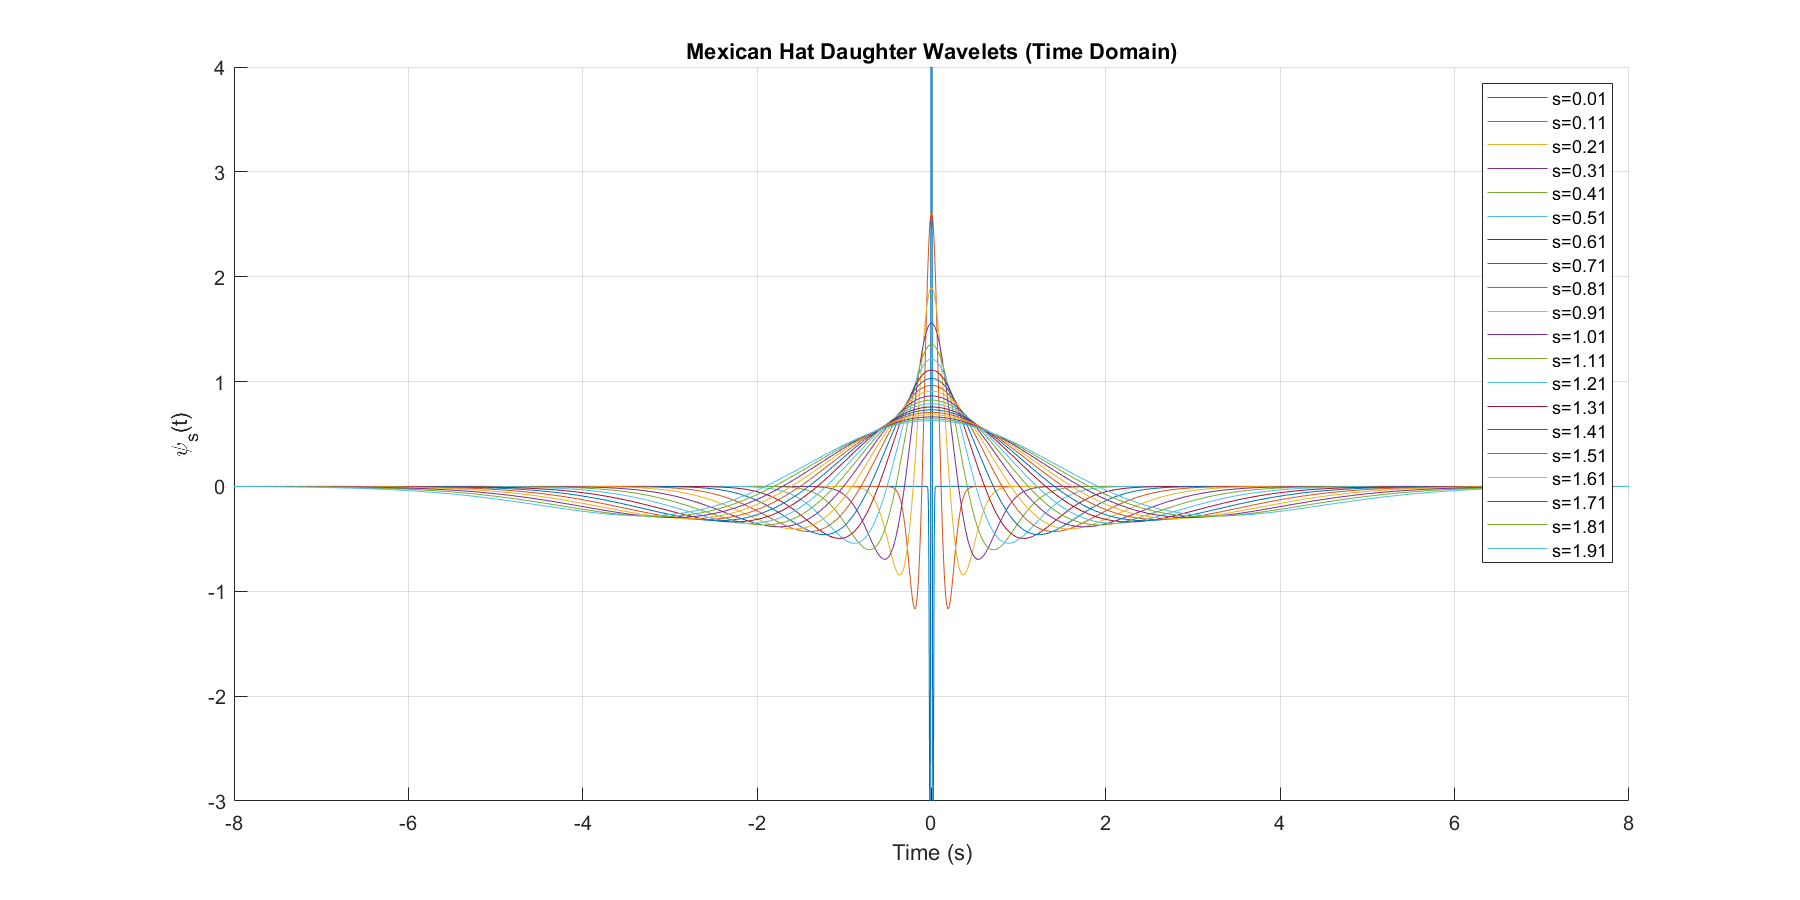


% Section 1.2 (iv & v) - Mexican hat daughter wavelets


clearvars; close all; clc;


%% Parameters
fs = 250;                   % Sampling frequency
N = 3000;                   % Data length
t = (-N:N)/fs;              % Time vector
s = 0.01:0.1:2;             % Scaling factors

%% Mexican hat wavelet 
m = @(tt) (1/sqrt(2*pi))*(1 - tt.^2).*exp(-tt.^2/2);
E = trapz(t,m(t).^2);
m_norm = @(tt) m(tt)/sqrt(E);

%% Plot all daughter wavelets in one figure
figure; hold on;
set(gcf,'Position',[100 100 1200 600]);
for k = 1:length(s)
    wavelt = (1/sqrt(s(k))) * m_norm(t/s(k));
    plot(t,wavelt,'DisplayName',['s=' num2str(s(k))]);
end
xlabel('Time (s)'), ylabel('\psi_s(t)')
title('Mexican Hat Daughter Wavelets (Time Domain)')
xlim([-8 8]);
ylim([-3 4]);
legend show; grid on; hold off;

%% Verification table: mean, energy, effective support
means = zeros(size(s));
energies = zeros(size(s));
support_width = zeros(size(s));

for k = 1:length(s)
    wavelt = (1/sqrt(s(k))) * m_norm(t/s(k));
    
    % Zero mean & unity energy
    means(k) = trapz(t,wavelt);        
    energies(k) = trapz(t,wavelt.^2);  
    
    % Compact support: width where |ψ| > threshold
    thresh = 1e-3 * max(abs(wavelt));
    idx = find(abs(wavelt) > thresh);
    support_width(k) = t(idx(end)) - t(idx(1));
end

% Round means to 2 decimal places for display
means = round(means, 2);

T = table(s', means', energies', support_width', ...
          'VariableNames', {'Scale','Mean','Energy','SupportWidth'});
disp(T)

    Scale    Mean    Energy    SupportWidth
    _____    ____    ______    ____________

    0.01      0        1           0.088   
    0.11      0        1           0.968   
    0.21      0        1           1.856   
    0.31      0        1           2.744   
    0.41      0        1           3.632   
    0.51      0        1            4.52   
    0.61      0        1           5.408   
    0.71      0        1           6.296   
    0.81      0        1           7.184   
    0.91      0        1           8.064   
    1.01      0        1           8.952   
    1.11      0        1            9.84   
    1.21      0        1          10.728   
    1.31      0        1          11.616   
    1.41      0        1          12.504   
    1.51      0        1          13.392   
    1.61      0        1           14.28   
    1.71      0        1   

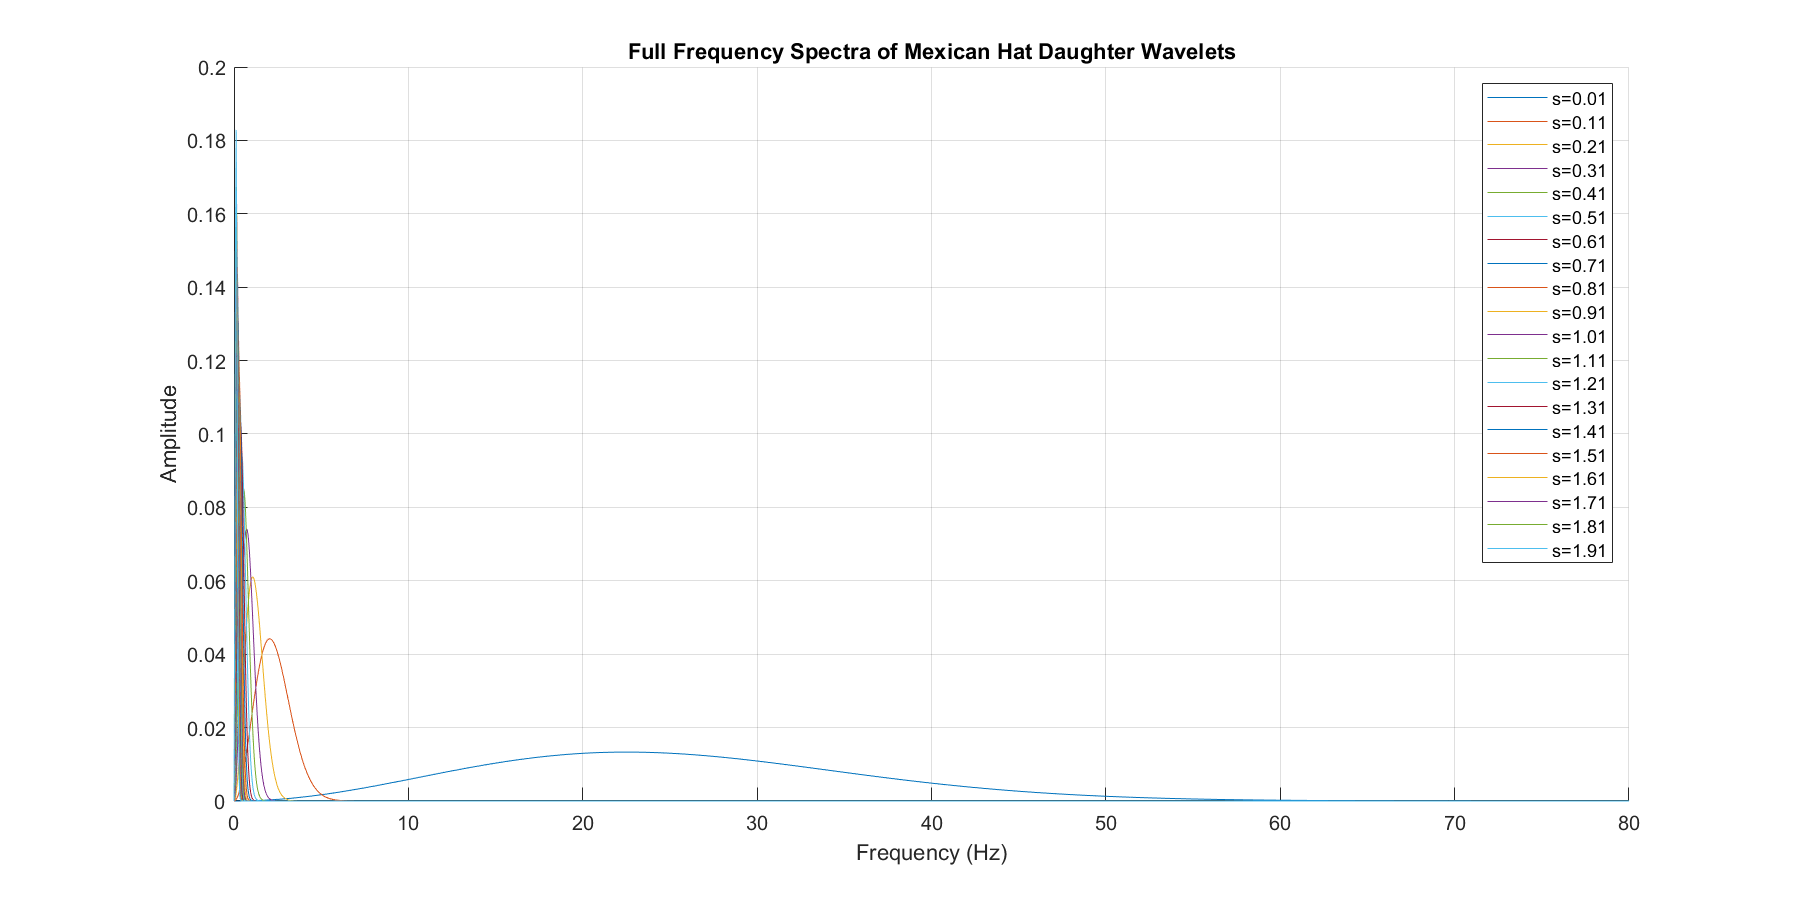

%% Part (vi) - Frequency spectra of Mexican Hat daughter wavelets

figure('Name','Full Spectrum: Mexican Hat Daughter Wavelets','NumberTitle','off'); 
set(gcf,'Position',[100 100 1200 600]);
hold on;

for k = 1:length(s)
    wavelt = (1/sqrt(s(k))) * m_norm(t/s(k));   % Daughter wavelet
    
    % FFT-based spectrum
    Fwavelt = fft(wavelt)/length(wavelt);
    hz = linspace(0, fs/2, floor(length(wavelt)/2)+1);
    plot(hz, 2*abs(Fwavelt(1:length(hz))), 'DisplayName',['s=' num2str(s(k))]);
end

xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Full Frequency Spectra of Mexican Hat Daughter Wavelets')
legend show, grid on; hold off;
xlim([0 80]);

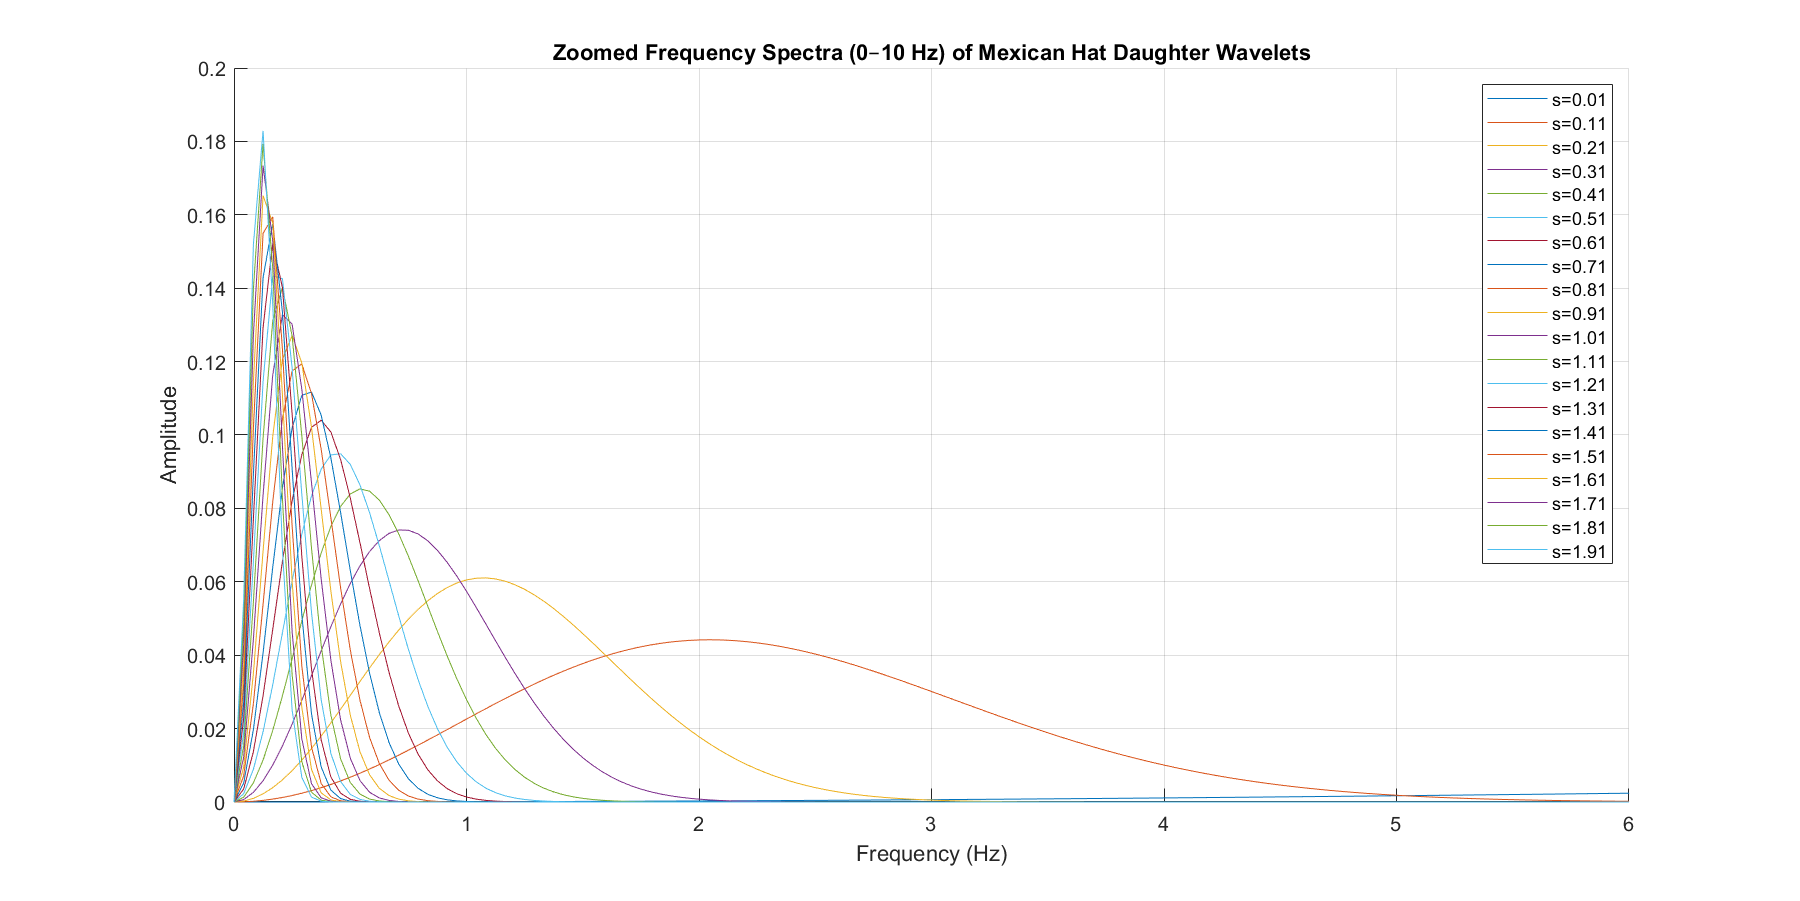



% Zoomed-in spectrum plot (0-10 Hz)
figure('Name','Zoomed Spectrum: Mexican Hat Daughter Wavelets','NumberTitle','off'); 
set(gcf,'Position',[150 150 1200 600]);
hold on;

for k = 1:length(s)
    wavelt = (1/sqrt(s(k))) * m_norm(t/s(k));   % Daughter wavelet
    
    % FFT-based spectrum
    Fwavelt = fft(wavelt)/length(wavelt);
    hz = linspace(0, fs/2, floor(length(wavelt)/2)+1);
    plot(hz, 2*abs(Fwavelt(1:length(hz))), 'DisplayName',['s=' num2str(s(k))]);
end

xlabel('Frequency (Hz)'), ylabel('Amplitude')
title('Zoomed Frequency Spectra (0–10 Hz) of Mexican Hat Daughter Wavelets')
legend show, grid on; hold off;
xlim([0 6]);

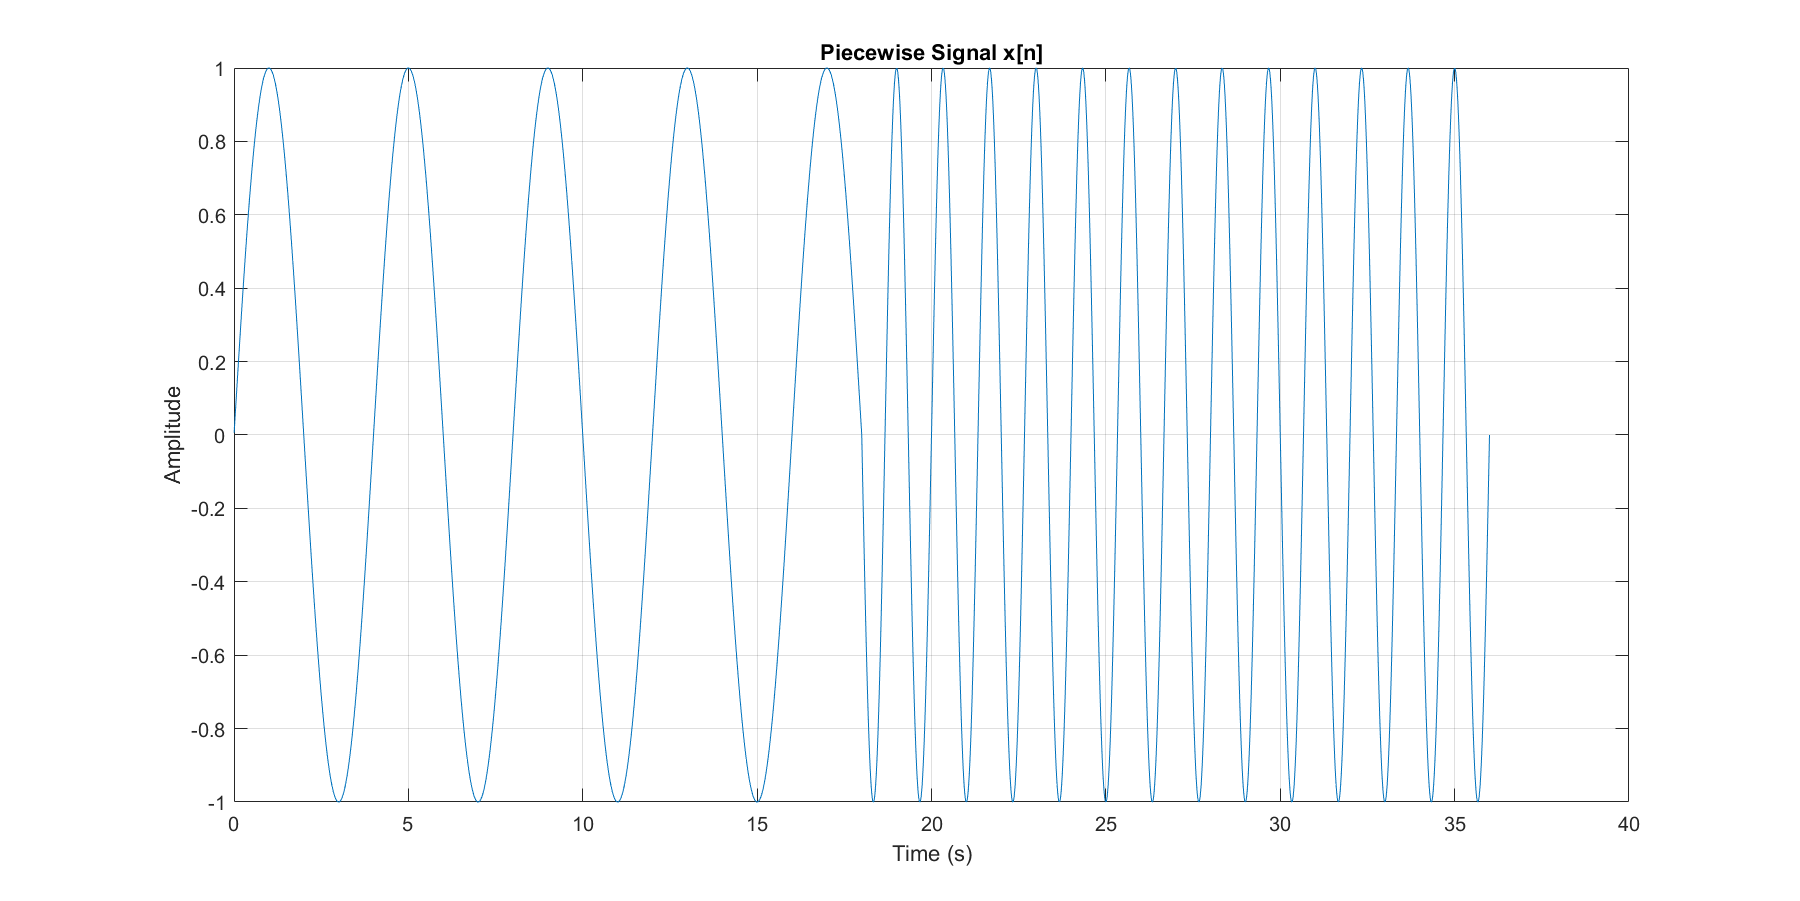

%% Parameters  
n = 1:3*N;         
t = n/fs;          

%% Create waveform using actual time
x = zeros(size(n));

% First segment: sin(0.5*pi*n/fs)
x(1:3*N/2) = sin(0.5*pi*(n(1:3*N/2)/fs));

% Second segment: sin(1.5*pi*n/fs)
x(3*N/2+1:end) = sin(1.5*pi*(n(3*N/2+1:end)/fs));

%% Plot the waveform
figure;
set(gcf,'Position',[150 150 1200 600]);
plot(t, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Piecewise Signal x[n]');
grid on;

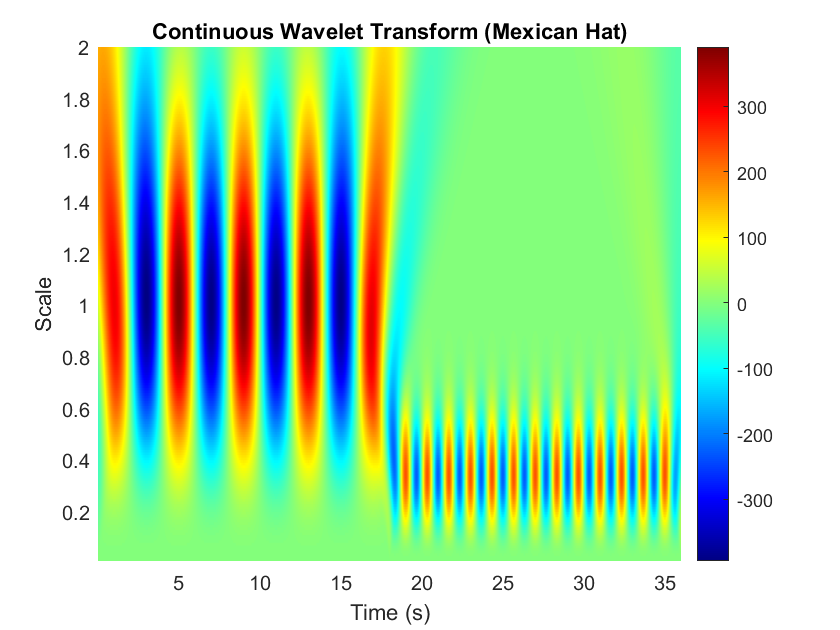

%% Mexican Hat mother wavelet (normalized)
wavelet_mother = @(tt) (1/sqrt(2*pi))*(1 - tt.^2).*exp(-tt.^2/2);
E = trapz((-N:N)/fs, wavelet_mother((-N:N)/fs).^2);   % Energy
wavelet_norm = @(tt) wavelet_mother(tt)/sqrt(E);       % Normalized
s_values = 0.01:0.01:2; 
%% Continuous Wavelet Transform (CWT) using convolution
coeffs = zeros(length(s_values), length(x));

for k = 1:length(s_values)
    s = s_values(k);
    wavelt = (1/sqrt(s)) * wavelet_norm((-N:N)/(fs*s));  % Scaled wavelet
    coeffs(k,:) = conv(x, wavelt, 'same');               % Convolution for translation
end

%% Plot Scale-Time Spectrogram
figure('Name','CWT: Mexican Hat','NumberTitle','off');
h = pcolor(t, s_values, coeffs);
set(h, 'EdgeColor', 'none');
colormap jet;
xlabel('Time (s)');
ylabel('Scale');
title('Continuous Wavelet Transform (Mexican Hat)');
colorbar;
set(gca,'YDir','normal');  % Ensure scale increases upwards

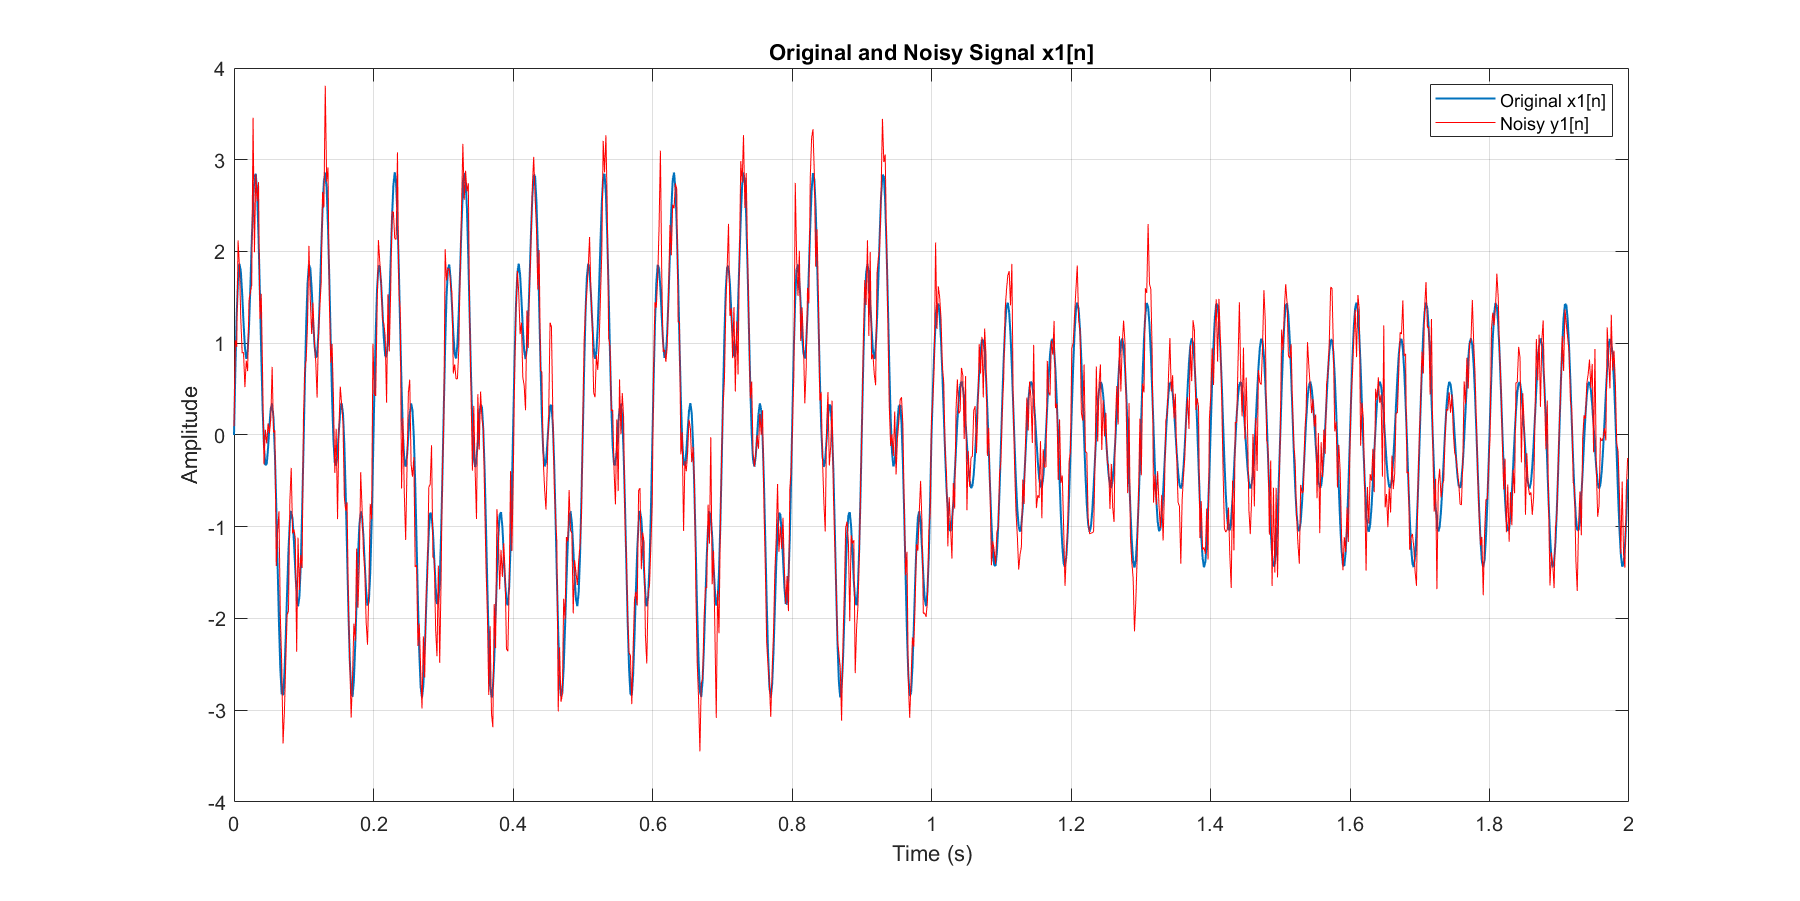


%% Parameters
fs = 512;          % Sampling frequency in Hz
n = 0:1023;        % Sample indices
t = n/fs;          % Time vector in seconds

%% -------------------- Signal x1[n] --------------------
x1n = zeros(size(n));

% First segment
x1n(1:512) = 2*sin(20*pi*t(1:512)) + sin(80*pi*t(1:512));

% Second segment
x1n(513:end) = 0.5*sin(40*pi*t(513:end)) + sin(60*pi*t(513:end));

% Add AWGN (10 dB)
y1n = awgn(x1n, 10, 'measured');

%% Plot original and noisy x1[n] together
figure('Name','Signal x1[n] with Noise','NumberTitle','off');
set(gcf,'Position',[150 150 1200 600]);
plot(t, x1n,  'LineWidth', 1); hold on;
plot(t, y1n, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Original and Noisy Signal x1[n]');
legend('Original x1[n]', 'Noisy y1[n]');
grid on;

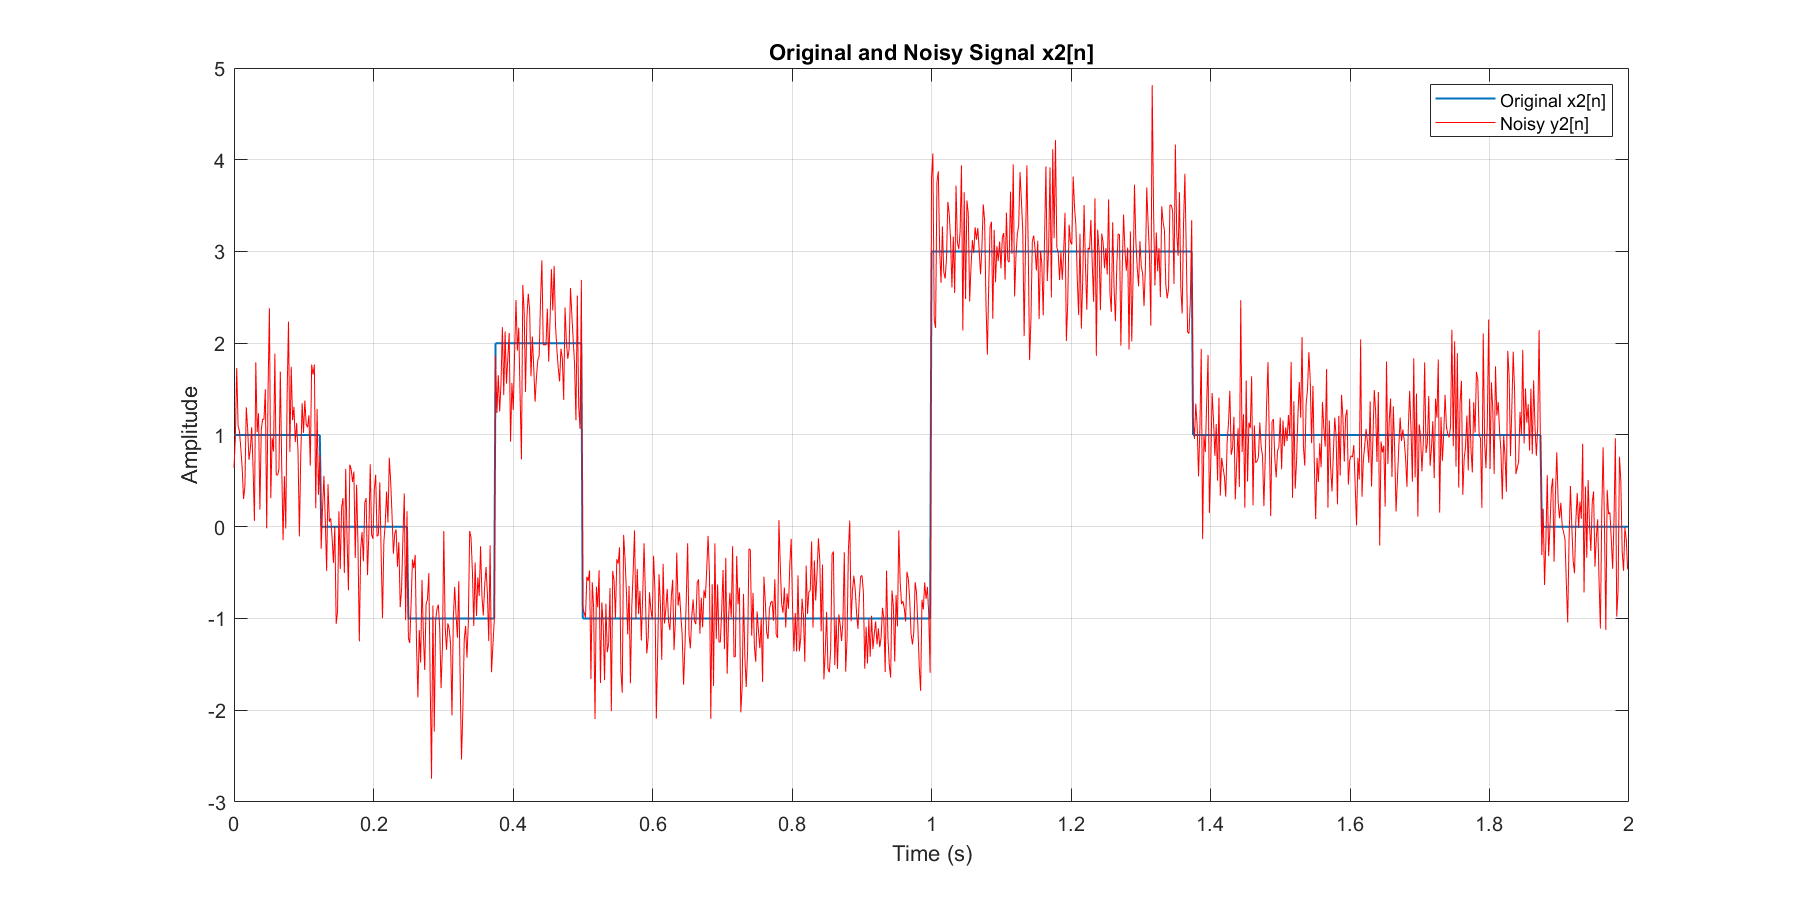


%% Signal x2[n]
x2n = zeros(size(n));

x2n(1:64)   = 1;
x2n(129:512) = -1;
x2n(193:256) = 2;    % overlapping handled automatically
x2n(513:704) = 3;
x2n(705:960) = 1;
% Remaining samples are 0

% Add AWGN (10 dB)
y2n = awgn(x2n, 10, 'measured');

%% Plot original and noisy x2[n] together
figure('Name','Signal x2[n] with Noise','NumberTitle','off');
set(gcf,'Position',[150 150 1200 600]);
plot(t, x2n, 'LineWidth', 1); hold on;
plot(t, y2n, 'r');
xlabel('Time (s)');
ylabel('Amplitude');
title('Original and Noisy Signal x2[n]');
legend('Original x2[n]', 'Noisy y2[n]');
grid on;

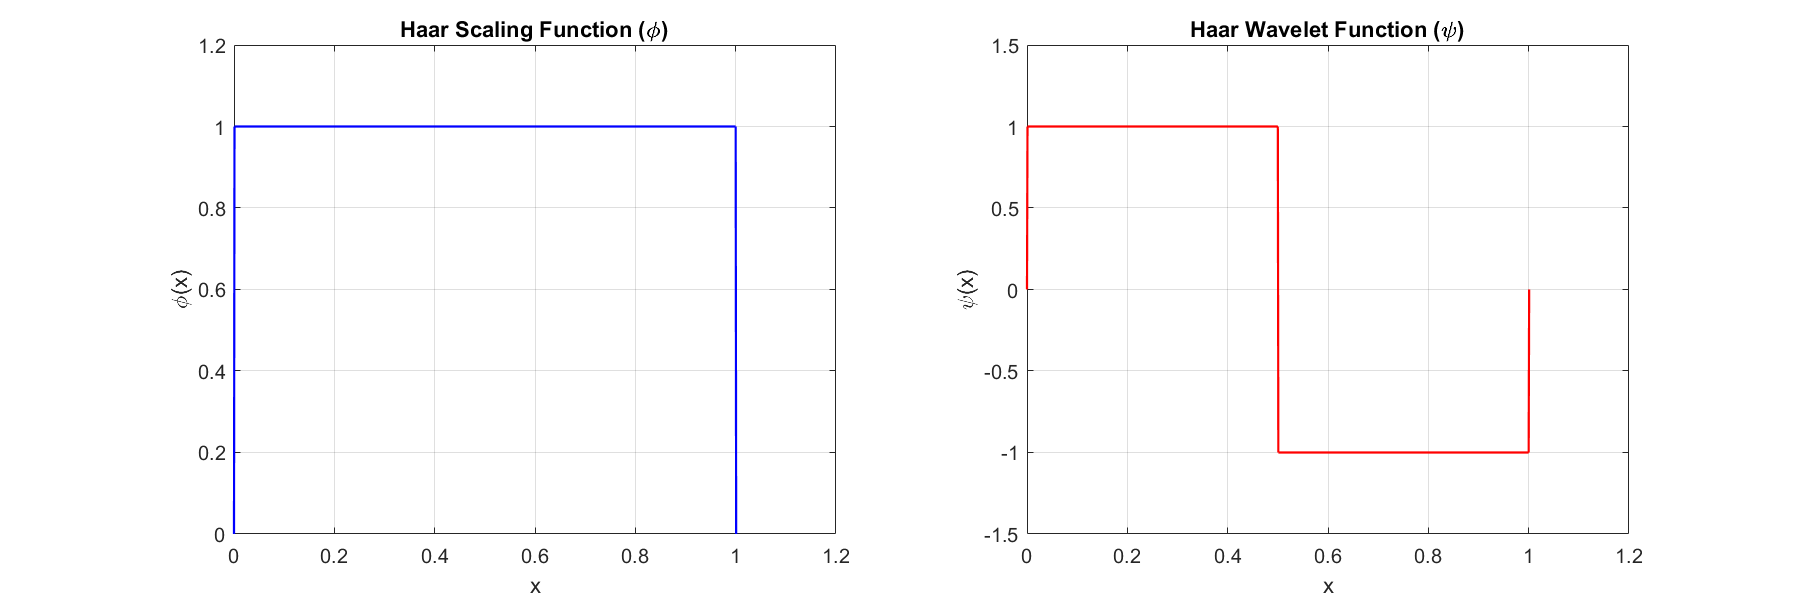

%% (ii) Observe morphology of Haar and db9


% Haar wavelet 
[phi_h, psi_h, x_h] = wavefun('haar', 10);

figure('Name','Haar: scaling & wavelet','NumberTitle','off');
set(gcf,'Position',[150 150 1200 400]);
subplot(1,2,1);
plot(x_h, phi_h, 'b', 'LineWidth', 1.1);
title('Haar Scaling Function (\phi)');
xlabel('x');
ylabel('\phi(x)');
grid on;

subplot(1,2,2);
plot(x_h, psi_h, 'r', 'LineWidth', 1.1);
title('Haar Wavelet Function (\psi)');
xlabel('x');
ylabel('\psi(x)');
grid on;

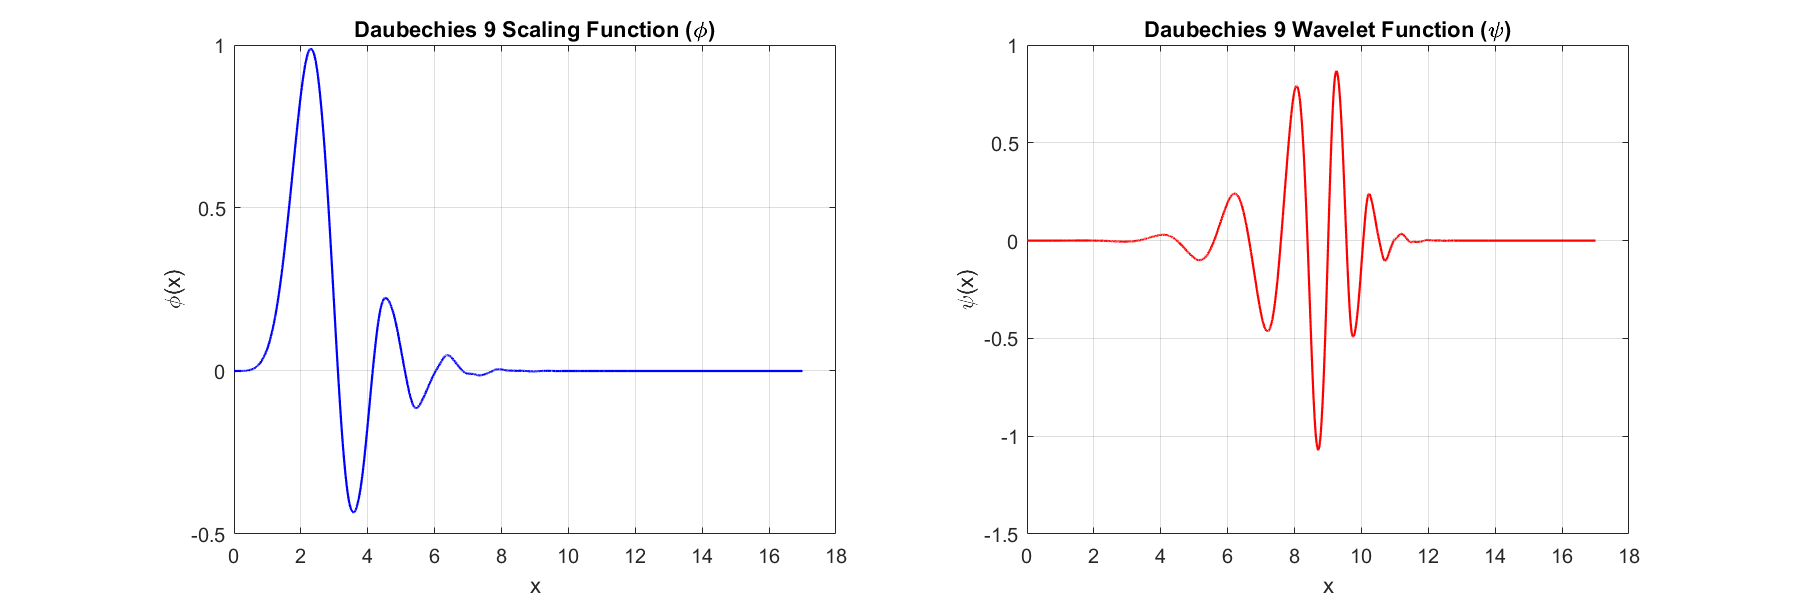

% Daubechies 9 wavelet 
[phi_db9, psi_db9, x_db9] = wavefun('db9', 10);

figure('Name','db9: scaling & wavelet','NumberTitle','off');
set(gcf,'Position',[150 150 1200 400]);
subplot(1,2,1);
plot(x_db9, phi_db9, 'b', 'LineWidth', 1.1);
title('Daubechies 9 Scaling Function (\phi)');
xlabel('x');
ylabel('\phi(x)');
grid on;

subplot(1,2,2);
plot(x_db9, psi_db9, 'r', 'LineWidth', 1.1);
title('Daubechies 9 Wavelet Function (\psi)');
xlabel('x');
ylabel('\psi(x)');
grid on;

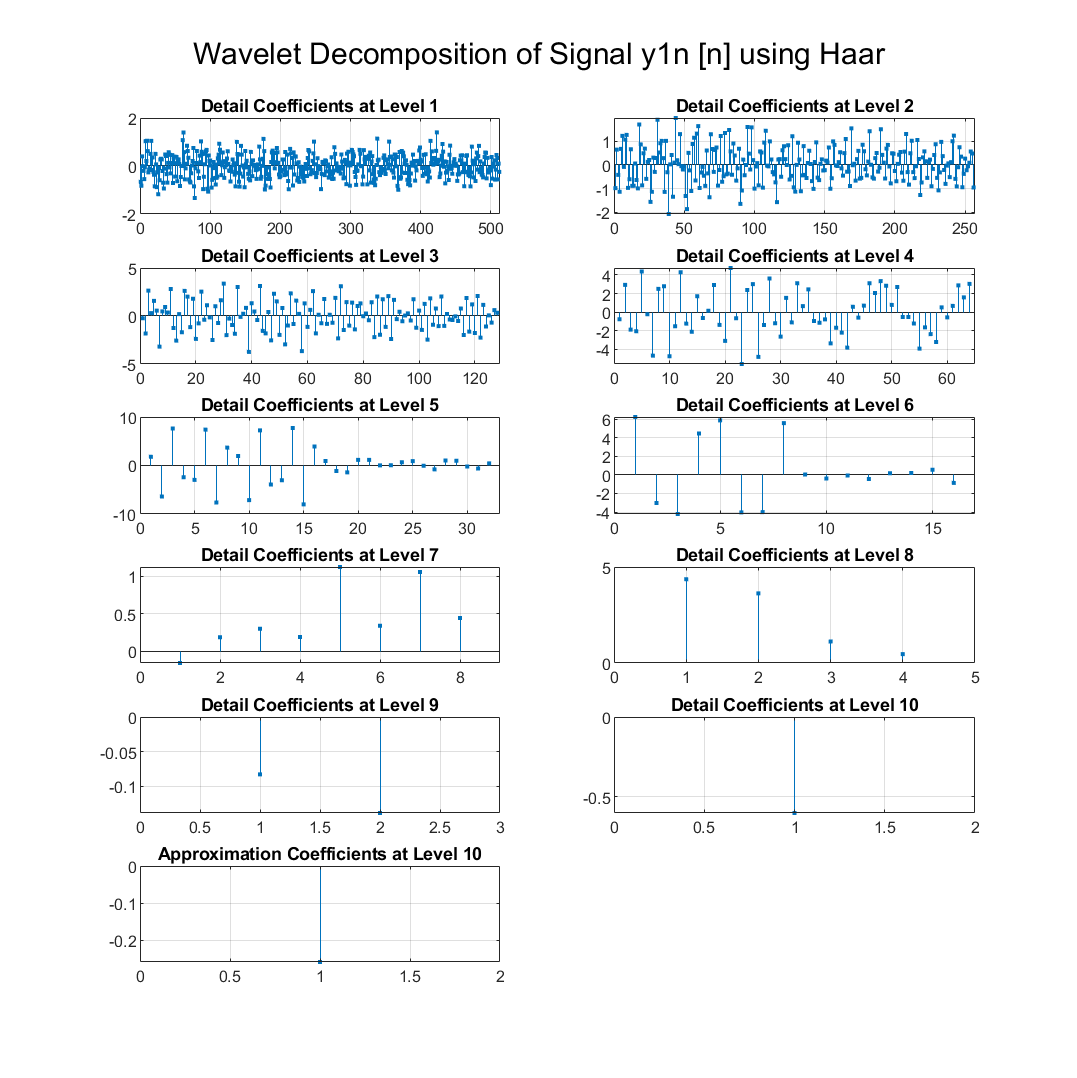

[C_haar_y1, L_haar_y1] = wavedec(y1n, 10, 'haar');
plot10Dec(C_haar_y1, L_haar_y1, 'y1n [n]', 'Haar');

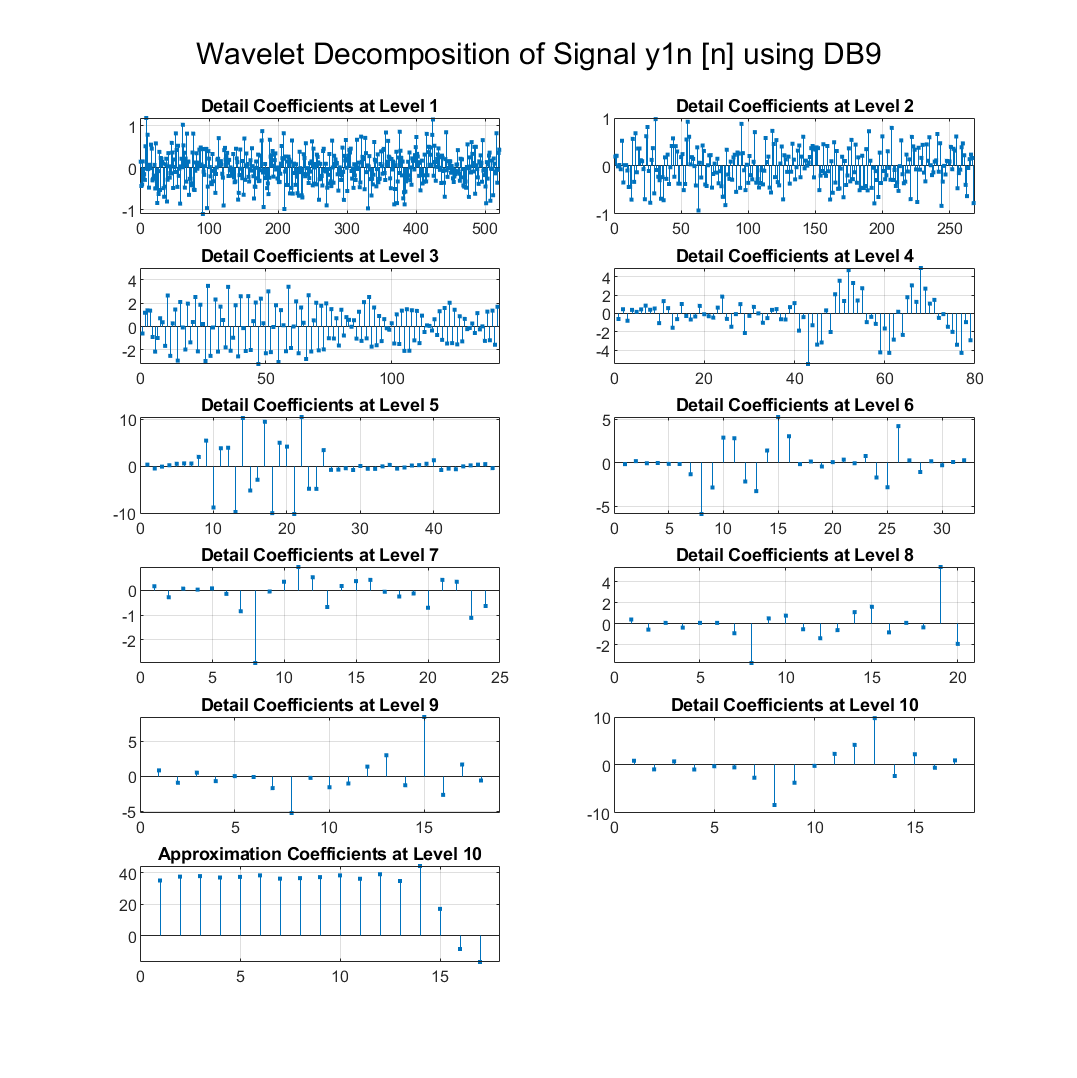

[C_db9_y1, L_db9_y1] = wavedec(y1n, 10, 'db9');
plot10Dec(C_db9_y1, L_db9_y1, 'y1n [n]', 'DB9');

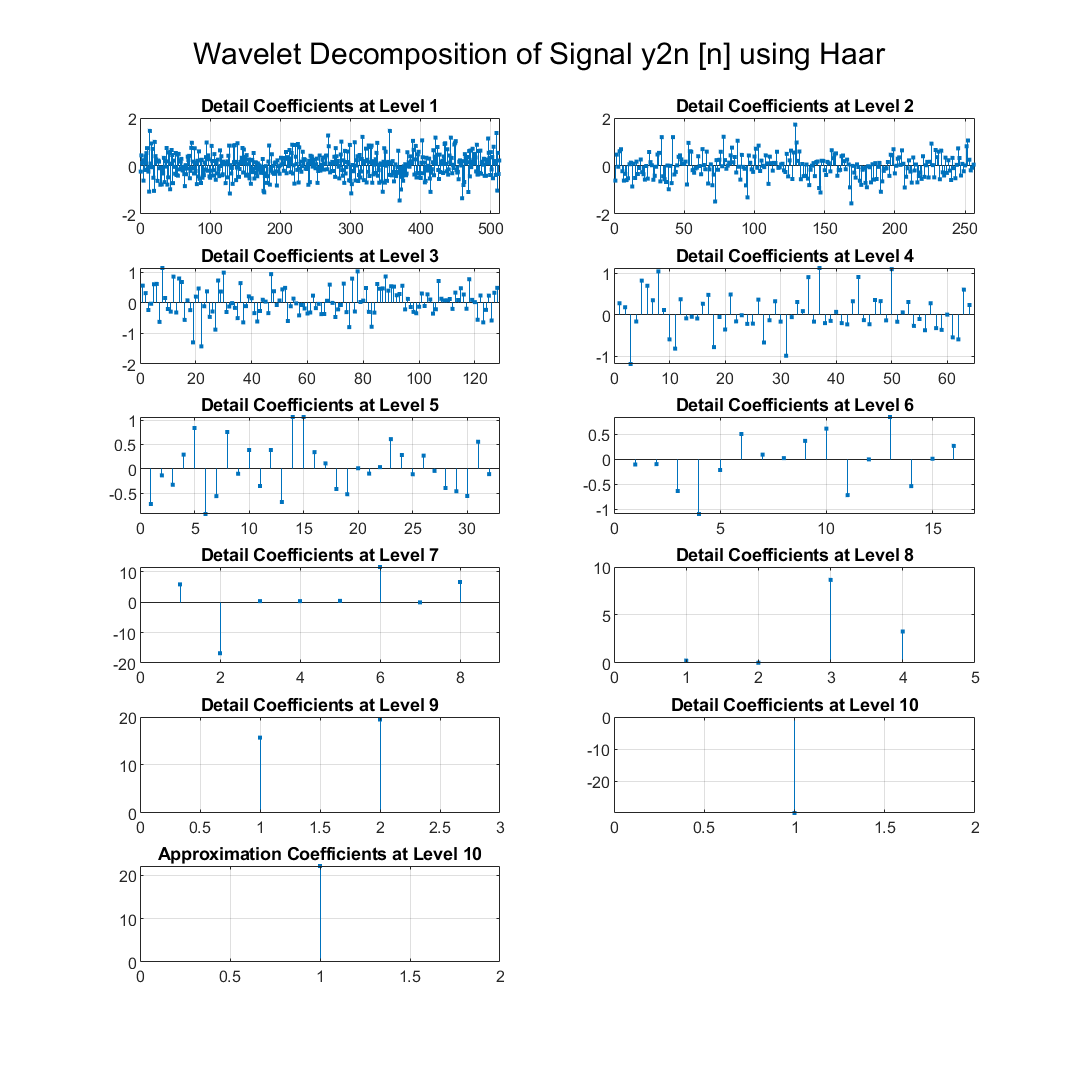

[C_haar_y2, L_haar_y2] = wavedec(y2n, 10, 'haar');
plot10Dec(C_haar_y2, L_haar_y2, 'y2n [n]', 'Haar');

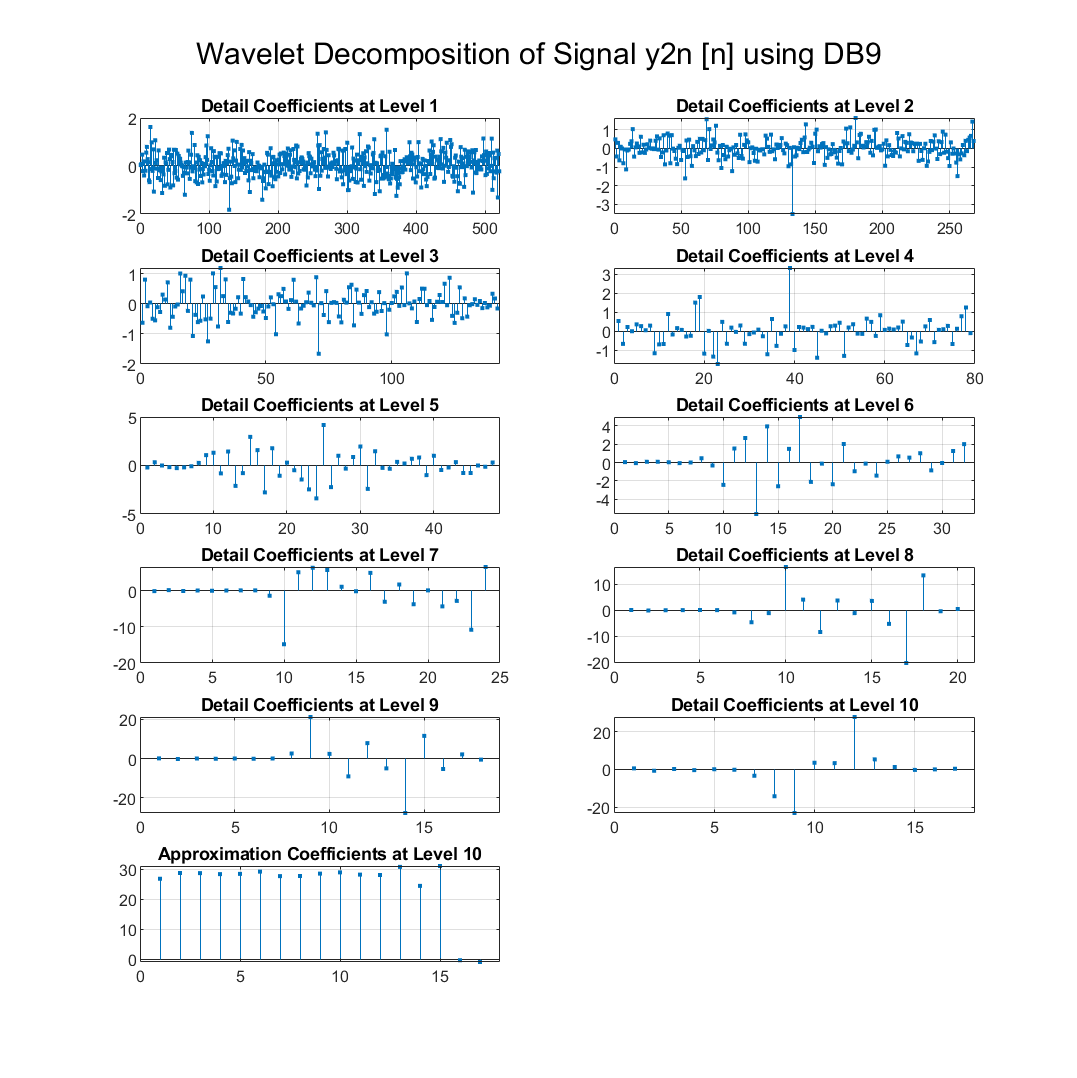

[C_db9_y2, L_db9_y2] = wavedec(y2n, 10, 'db9');
plot10Dec(C_db9_y2, L_db9_y2, 'y2n [n]', 'DB9');

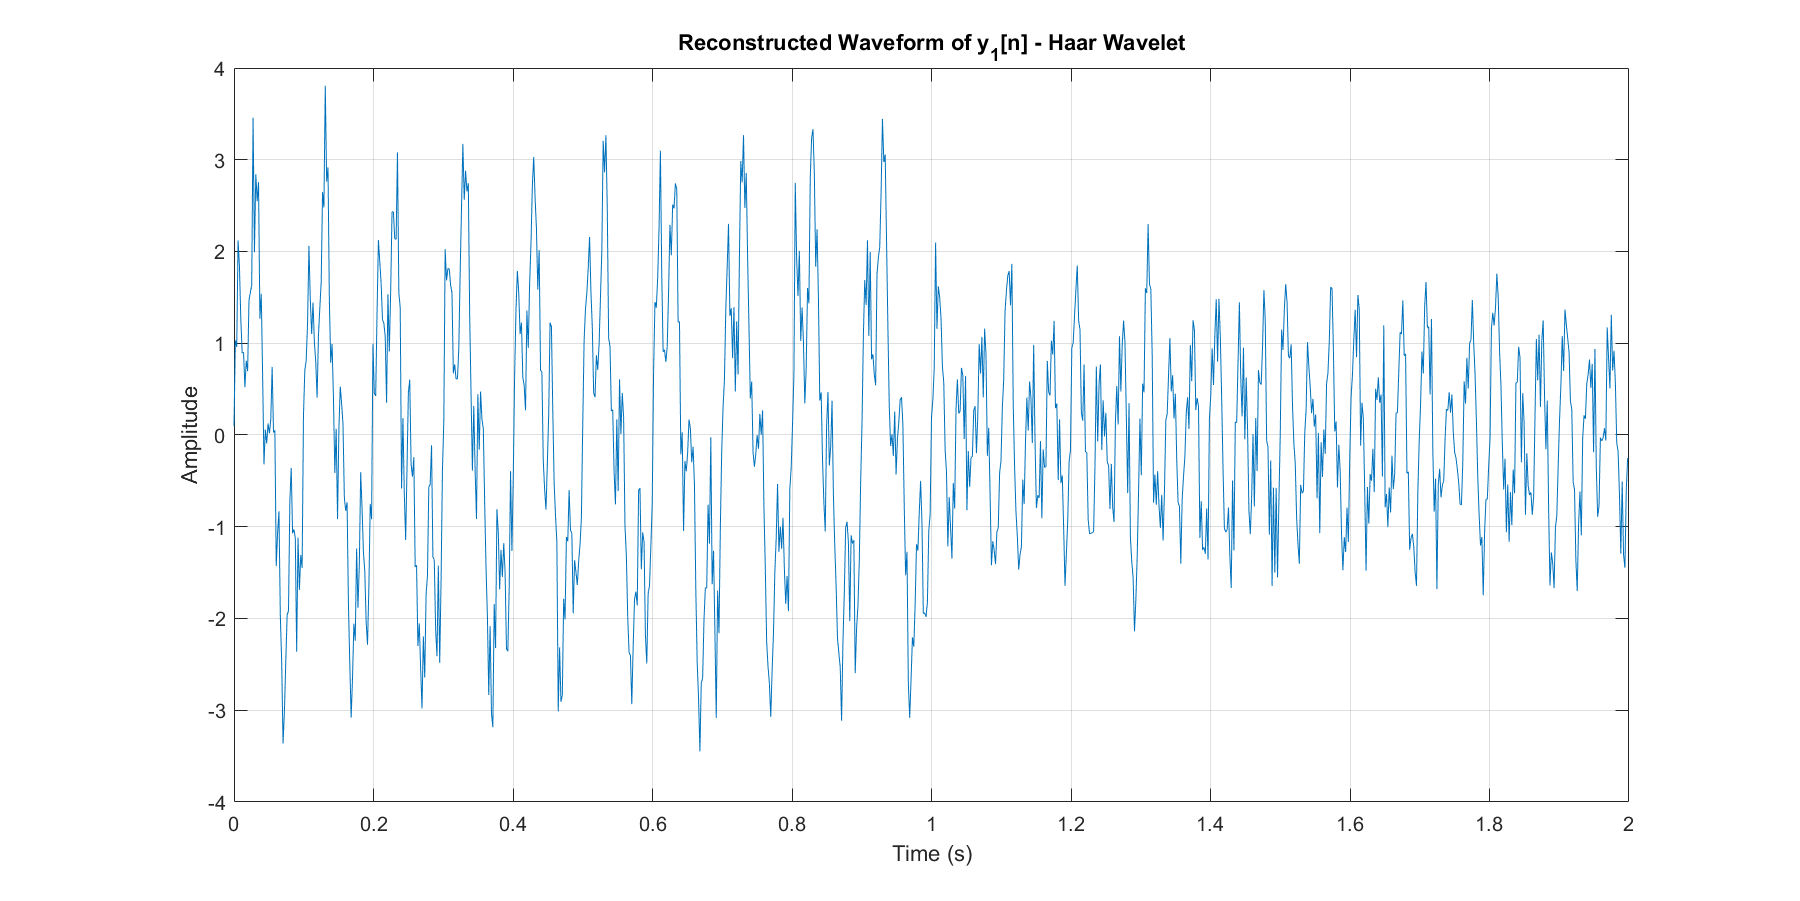


y1_haar_comps = cell(1,11);

for k = 1:10
    y1_haar_comps{k} = wrcoef('d', C_haar_y1, L_haar_y1, 'haar', k);
end
y1_haar_comps{11} = wrcoef('a', C_haar_y1, L_haar_y1, 'haar', 10);

% Sum all reconstructed components
y1_haar_recon = sum(cat(1, y1_haar_comps{:}), 1);

% Plot reconstructed signal
figure('Position', [100, 100, 1000, 400]);
set(gcf,'Position',[150 150 1200 600]);
plot(t, y1_haar_recon);
xlabel('Time (s)'); ylabel('Amplitude');
title('Reconstructed Waveform of y_1[n] - Haar Wavelet');
xlim([0 2]); grid on;


% Energy verification
E_orig = sum(y1n.^2);
E_recon = sum(y1_haar_recon.^2);
E_diff = abs(E_orig - E_recon);

fprintf('y1[n] - HAAR:\n');

y1[n] - HAAR:


fprintf('  Original Energy     = %.4f\n', E_orig);

  Original Energy     = 1756.0850


fprintf('  Reconstructed Energy = %.4f\n', E_recon);

  Reconstructed Energy = 1756.0850


fprintf('  Difference           = %.6e\n', E_diff);

  Difference           = 1.818989e-12


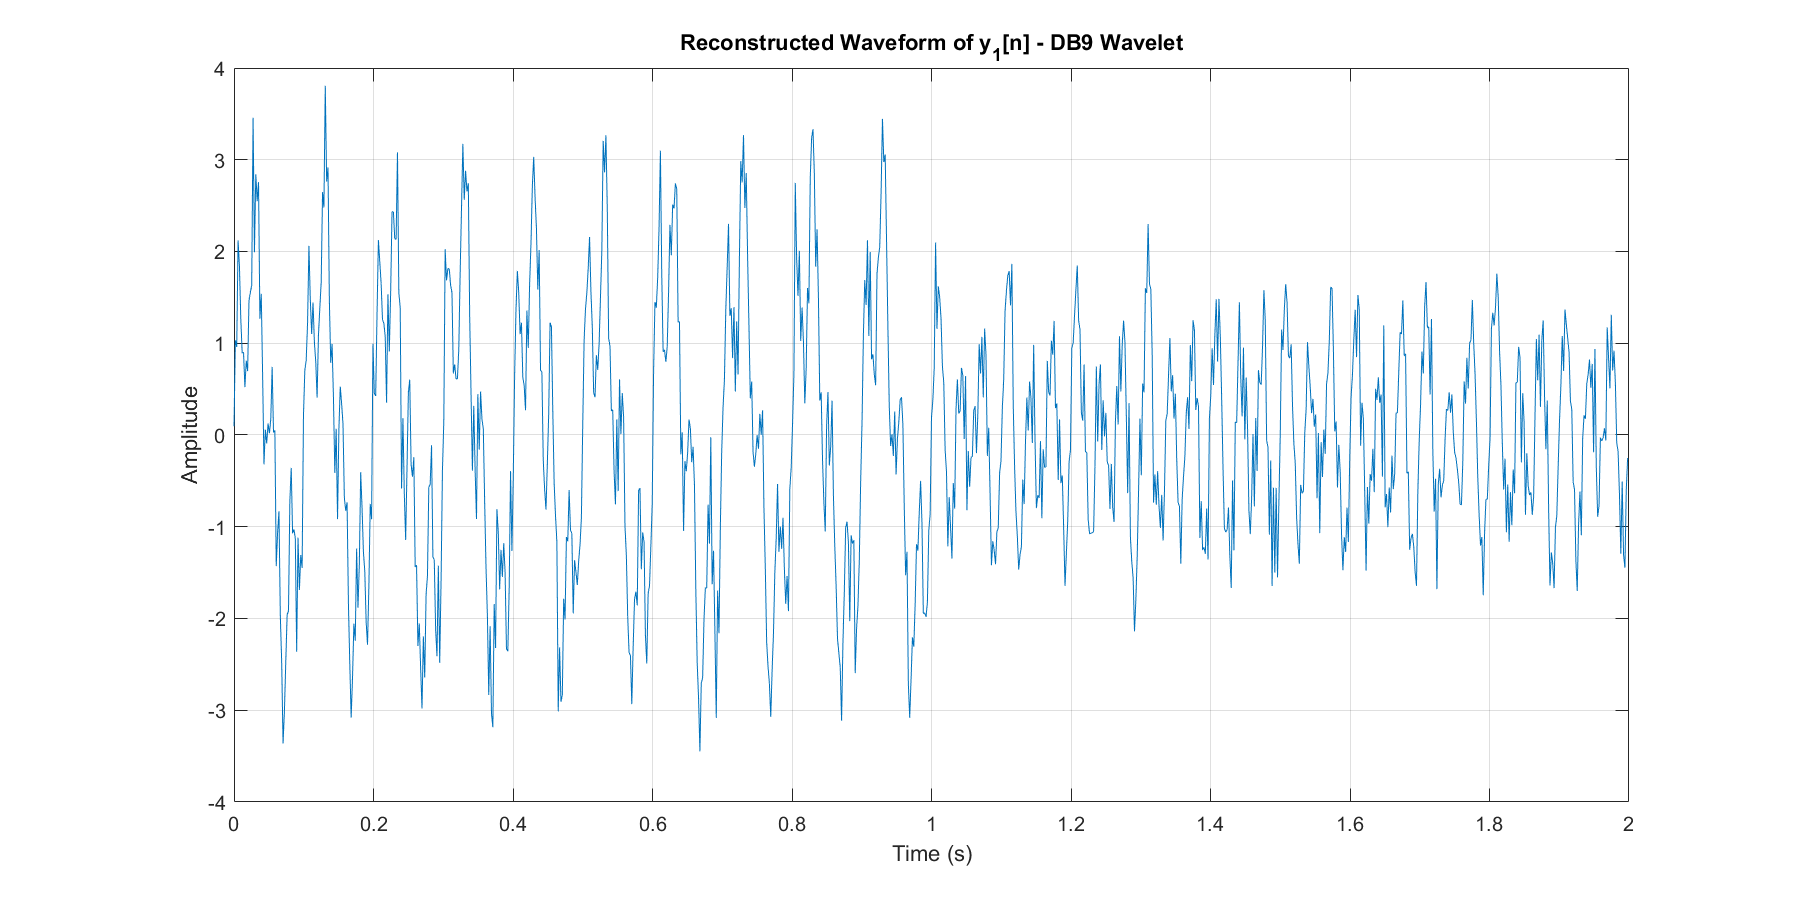

%% Reconstruction of A10, D10...D1 for y1[n] using DB9

y1_db9_comps = cell(1,11);

for k = 1:10
    y1_db9_comps{k} = wrcoef('d', C_db9_y1, L_db9_y1, 'db9', k);
end
y1_db9_comps{11} = wrcoef('a', C_db9_y1, L_db9_y1, 'db9', 10);

y1_db9_recon = sum(cat(1, y1_db9_comps{:}), 1);

figure();
set(gcf,'Position',[150 150 1200 600]);
plot(t, y1_db9_recon);
xlabel('Time (s)'); ylabel('Amplitude');
title('Reconstructed Waveform of y_1[n] - DB9 Wavelet');
xlim([0 2]); grid on;


E_orig = sum(y1n.^2);
E_recon = sum(y1_db9_recon.^2);
E_diff = abs(E_orig - E_recon);

fprintf('y1[n] - DB9:\n')

y1[n] - DB9:


fprintf('  Original Energy     = %.4f\n', E_orig);

  Original Energy     = 1756.0850


fprintf('  Reconstructed Energy = %.4f\n', E_recon);

  Reconstructed Energy = 1756.0850


fprintf('  Difference           = %.6e\n', E_diff);

  Difference           = 3.033572e-07


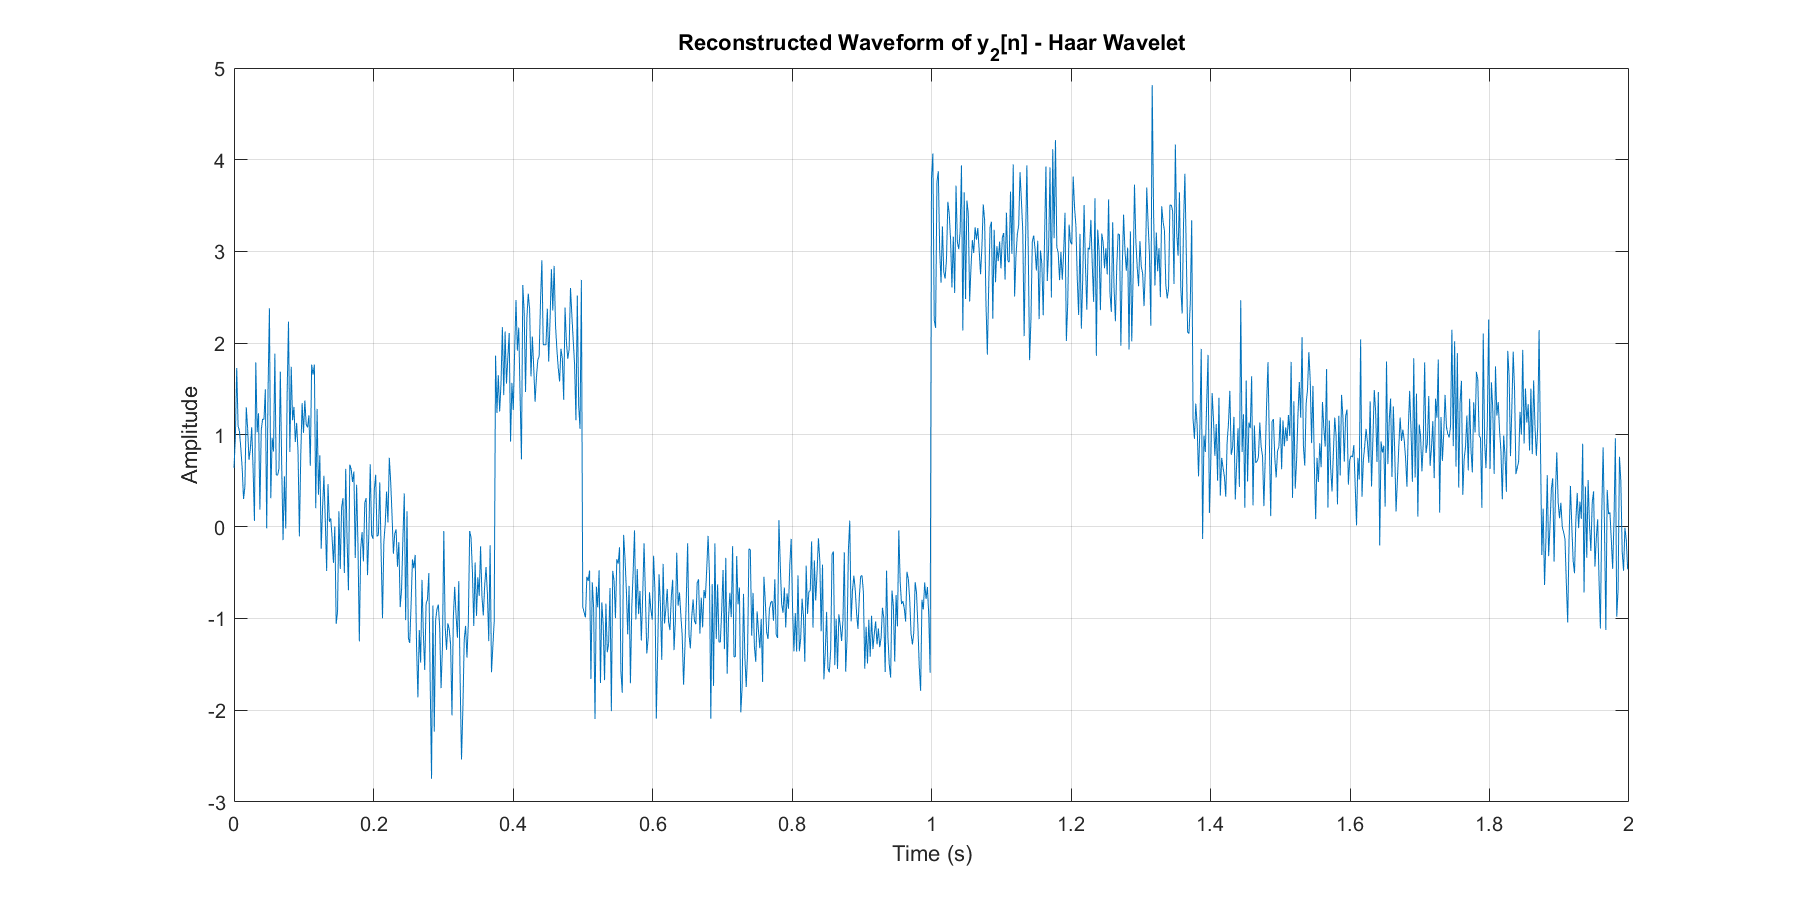

%% Reconstruction of A10, D10...D1 for y2[n] using HAAR

y2_haar_comps = cell(1,11);

for k = 1:10
    y2_haar_comps{k} = wrcoef('d', C_haar_y2, L_haar_y2, 'haar', k);
end
y2_haar_comps{11} = wrcoef('a', C_haar_y2, L_haar_y2, 'haar', 10);

y2_haar_recon = sum(cat(1, y2_haar_comps{:}), 1);

figure();
set(gcf,'Position',[150 150 1200 600]);
plot(t, y2_haar_recon);
xlabel('Time (s)'); ylabel('Amplitude');
title('Reconstructed Waveform of y_2[n] - Haar Wavelet');
xlim([0 2]); grid on;


E_orig = sum(y2n.^2);
E_recon = sum(y2_haar_recon.^2);
E_diff = abs(E_orig - E_recon);

fprintf('y2[n] - HAAR:\n');

y2[n] - HAAR:


fprintf('  Original Energy     = %.4f\n', E_orig);

  Original Energy     = 2823.8624


fprintf('  Reconstructed Energy = %.4f\n', E_recon);

  Reconstructed Energy = 2823.8624


fprintf('  Difference           = %.6e\n', E_diff);

  Difference           = 7.730705e-12


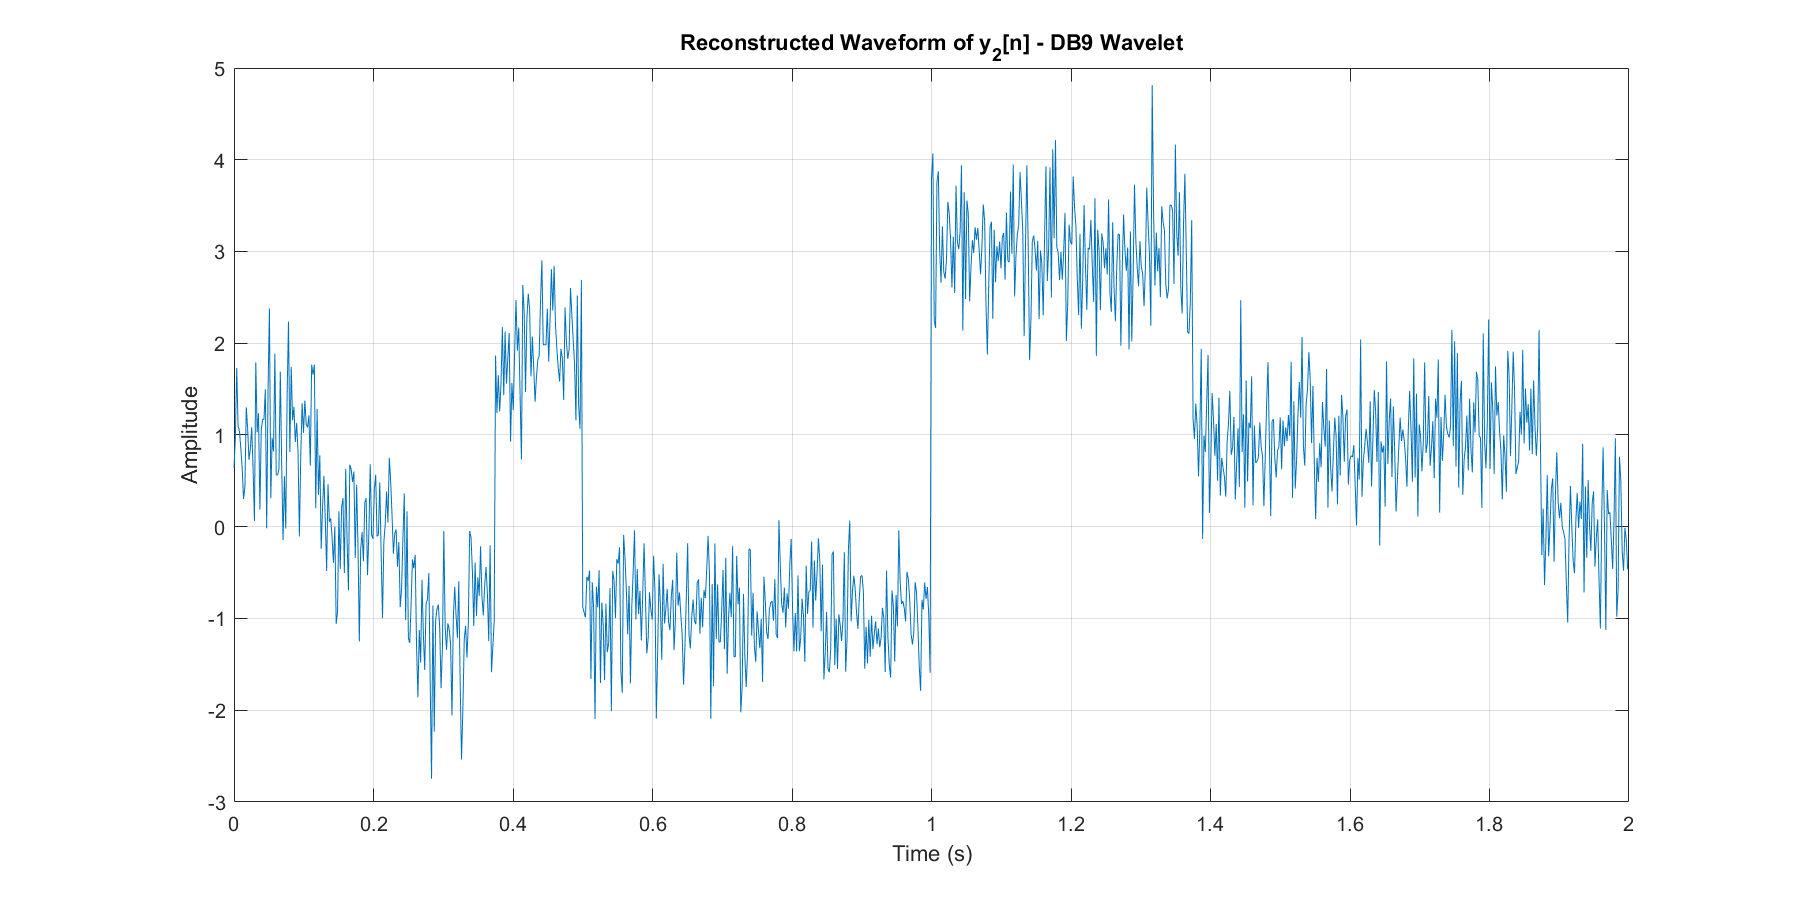


%%Reconstruction of A10, D10...D1 for y2[n] using DB9 

y2_db9_comps = cell(1,11);

for k = 1:10
    y2_db9_comps{k} = wrcoef('d', C_db9_y2, L_db9_y2, 'db9', k);
end
y2_db9_comps{11} = wrcoef('a', C_db9_y2, L_db9_y2, 'db9', 10);

y2_db9_recon = sum(cat(1, y2_db9_comps{:}), 1);

figure();
set(gcf,'Position',[150 150 1200 600]);
plot(t, y2_db9_recon);
xlabel('Time (s)'); ylabel('Amplitude');
title('Reconstructed Waveform of y_2[n] - DB9 Wavelet');
xlim([0 2]); grid on;


E_orig = sum(y2n.^2);
E_recon = sum(y2_db9_recon.^2);
E_diff = abs(E_orig - E_recon);

fprintf('y2[n] - DB9:\n');

y2[n] - DB9:



fprintf('  Original Energy     = %.4f\n', E_orig);

  Original Energy     = 2823.8624


fprintf('  Reconstructed Energy = %.4f\n', E_recon);

  Reconstructed Energy = 2823.8624


fprintf('  Difference           = %.6e\n', E_diff);

  Difference           = 4.600629e-07


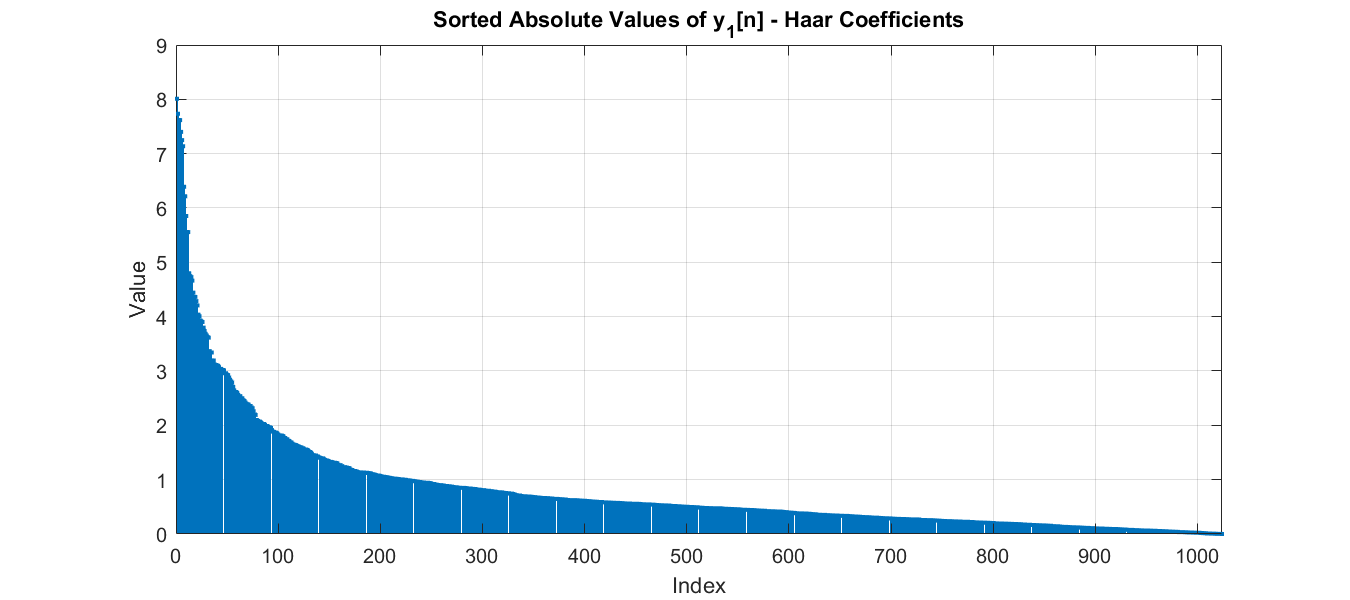

% 2.3. Signal Denoising with DWT
C_haar_y1_abs = abs(C_haar_y1); % Calculating the absolute values
sorted_C_haar_y1_abs = sort(C_haar_y1_abs, 'descend');  % Sorting in descending order

C_db9_y1_abs = abs(C_db9_y1); % Calculating the absolute values
sorted_C_db9_y1_abs = sort(C_db9_y1_abs, 'descend');  % Sorting in descending order

C_haar_y2_abs = abs(C_haar_y2); % Calculating the absolute values
sorted_C_haar_y2_abs = sort(C_haar_y2_abs, 'descend');  % Sorting in descending order

C_db9_y2_abs = abs(C_db9_y2); % Calculating the absolute values
sorted_C_db9_y2_abs = sort(C_db9_y2_abs, 'descend');  % Sorting in descending order

figure('Name','y_1[n] - Haar Coefficients','NumberTitle','off','Position',[100,100,900,400]);
stem(sorted_C_haar_y1_abs, '.');
title('Sorted Absolute Values of y_1[n] - Haar Coefficients');
xlabel('Index'); ylabel('Value');
xlim([0 1024]);
grid on;

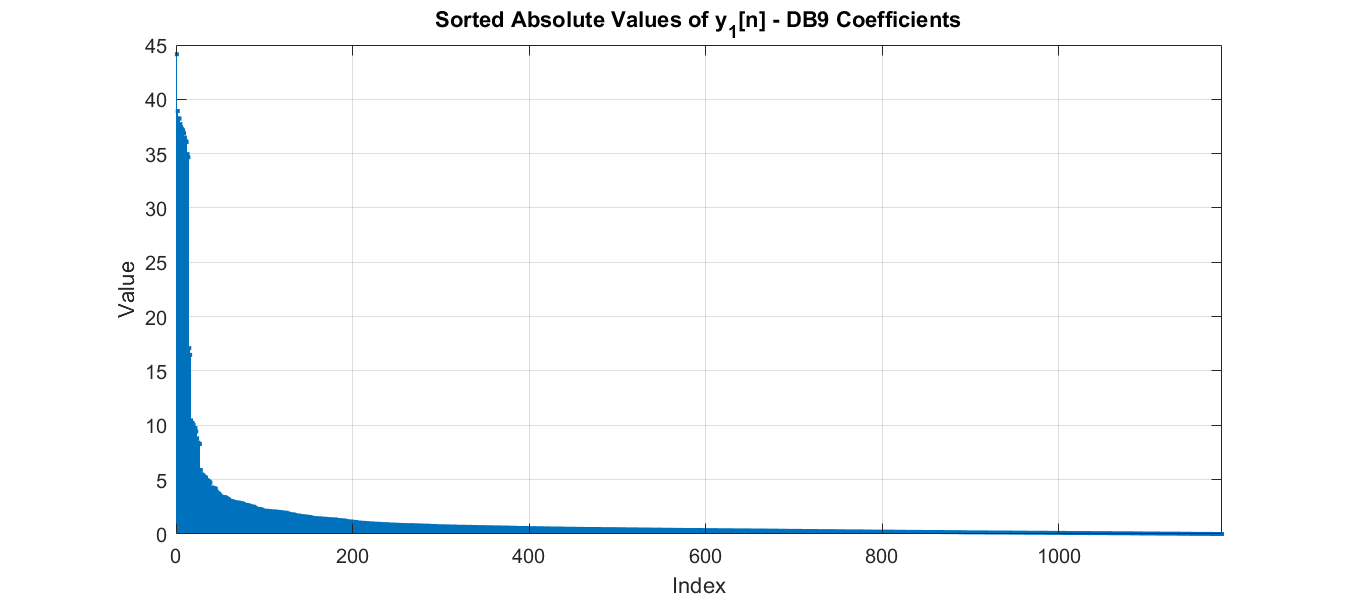


figure('Name','y_1[n] - DB9 Coefficients','NumberTitle','off','Position',[150,150,900,400]);
stem(sorted_C_db9_y1_abs, '.');
title('Sorted Absolute Values of y_1[n] - DB9 Coefficients');
xlabel('Index'); ylabel('Value');
xlim([0 1185]);
grid on;

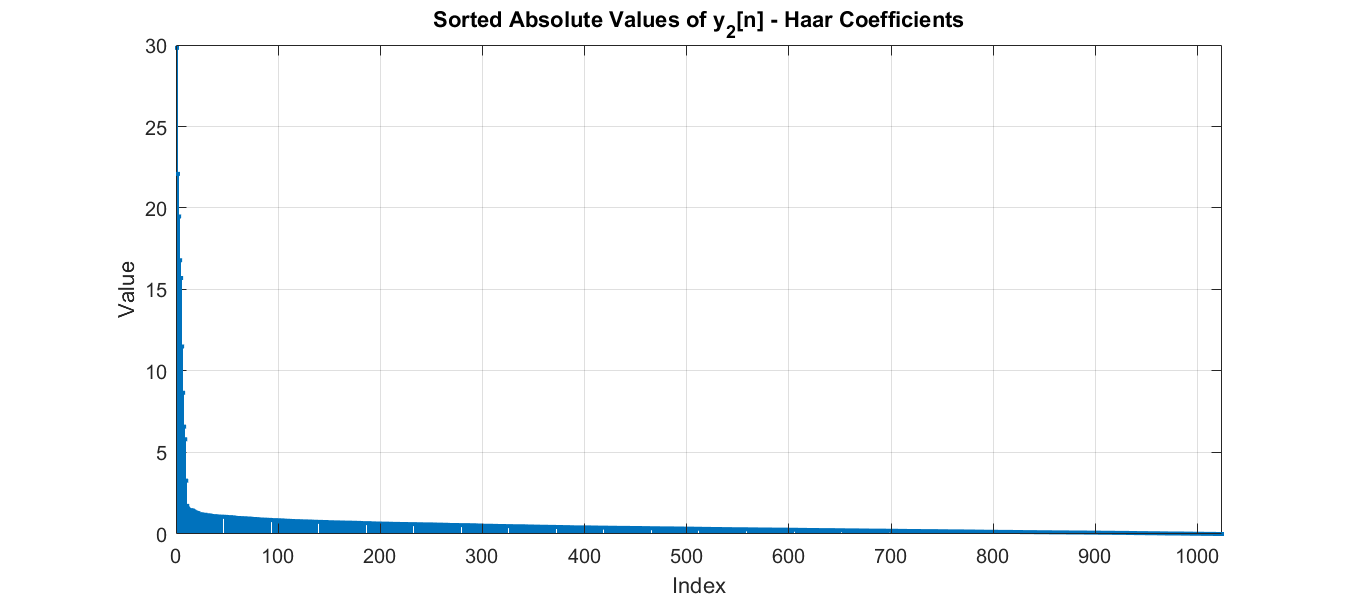


figure('Name','y_2[n] - Haar Coefficients','NumberTitle','off','Position',[200,200,900,400]);
stem(sorted_C_haar_y2_abs, '.');
title('Sorted Absolute Values of y_2[n] - Haar Coefficients');
xlabel('Index'); ylabel('Value');
xlim([0 1024]);
grid on;

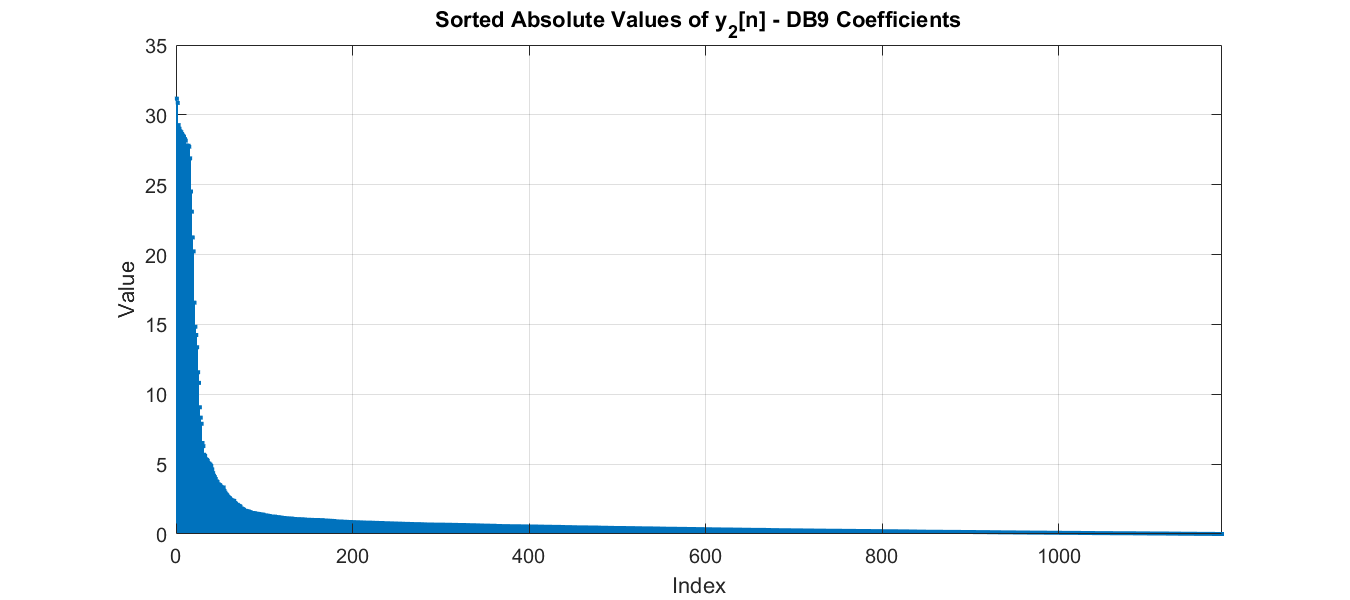


figure('Name','y_2[n] - DB9 Coefficients','NumberTitle','off','Position',[250,250,900,400]);
stem(sorted_C_db9_y2_abs, '.');
title('Sorted Absolute Values of y_2[n] - DB9 Coefficients');
xlabel('Index'); ylabel('Value');
xlim([0 1185]);
grid on;

% (ii) Select a threshold for coefficients. Reconstruct the signal with suppressed coefficients

C_haar_y1_denoise = C_haar_y1;
C_haar_y1_denoise(C_haar_y1_abs < 0.75) = 0;
y1_haar_denoised = waverec(C_haar_y1_denoise, L_haar_y1, 'haar');

C_db9_y1_denoise = C_db9_y1;
C_db9_y1_denoise(C_db9_y1_abs < 1) = 0;
y1_db9_denoised = waverec(C_db9_y1_denoise, L_db9_y1, 'db9');

C_haar_y2_denoise = C_haar_y2;
C_haar_y2_denoise(C_haar_y2_abs < 2.5) = 0;
y2_haar_denoised = waverec(C_haar_y2_denoise, L_haar_y2, 'haar');

C_db9_y2_denoise = C_db9_y2;
C_db9_y2_denoise(C_db9_y2_abs < 1.25) = 0;
y2_db9_denoised = waverec(C_db9_y2_denoise, L_db9_y2, 'db9');

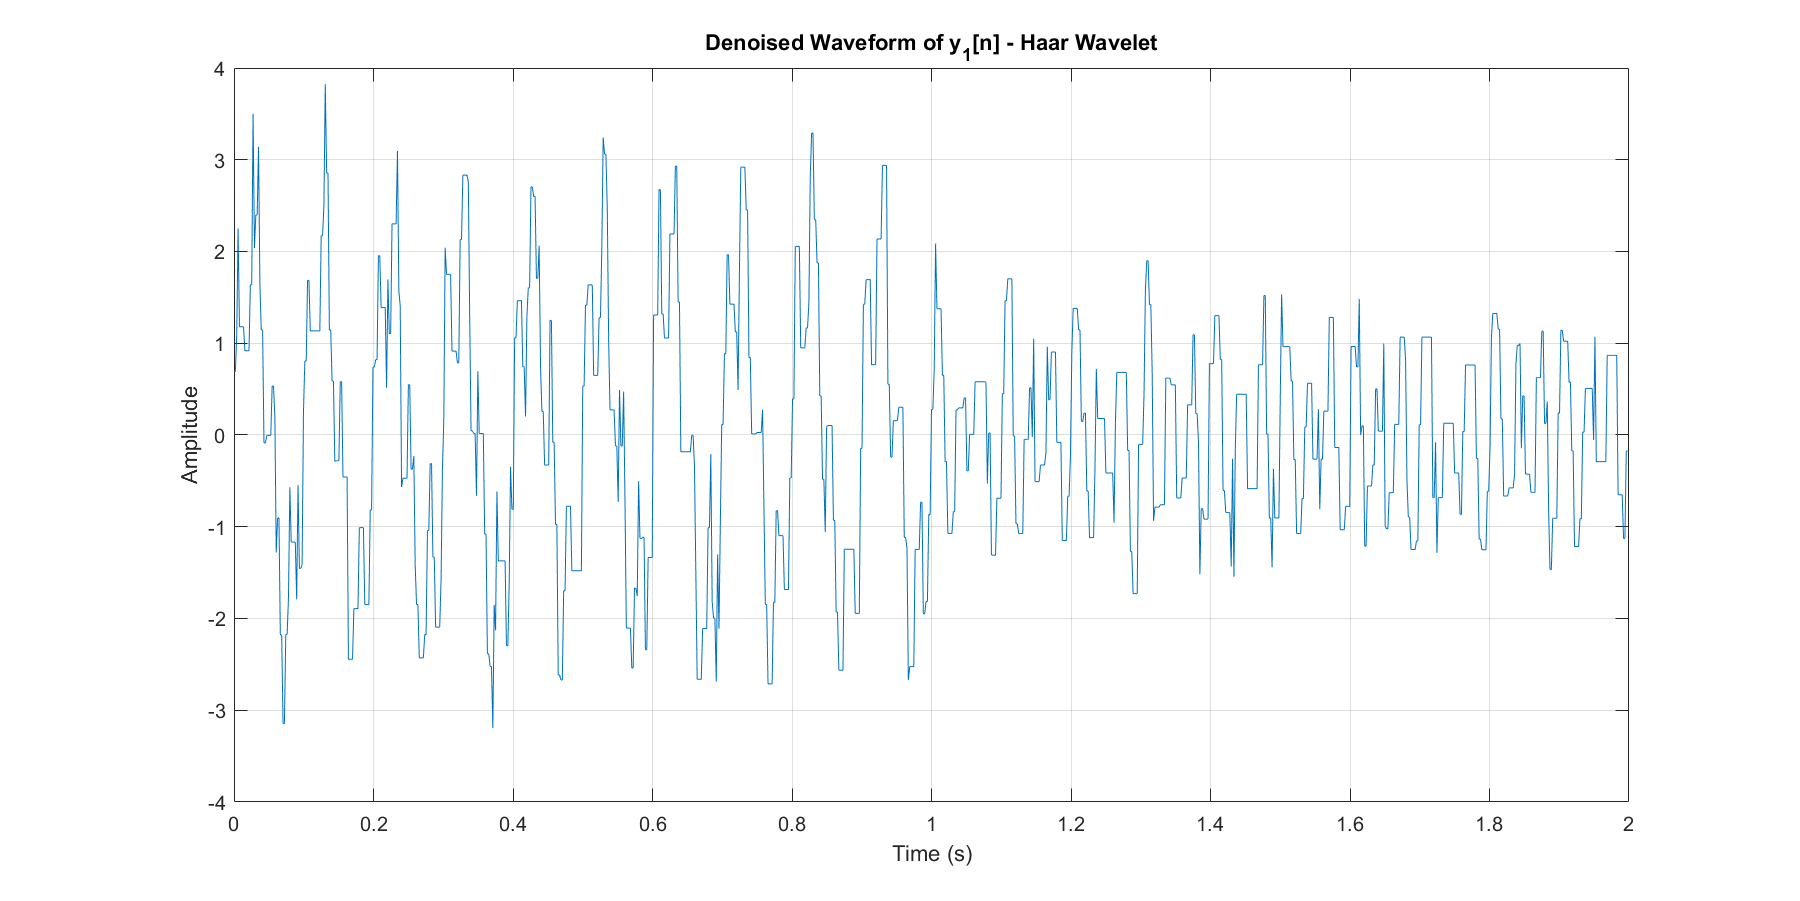

% Plot the denoised reconstructed waveforms (separate figures)

% --- y1[n] - Haar ---
figure('Name','y_1[n] - Haar Denoised','NumberTitle','off');
set(gcf,'Position',[150 150 1200 600]);
plot(t, y1_haar_denoised);
xlabel('Time (s)');
ylabel('Amplitude');
title('Denoised Waveform of y_1[n] - Haar Wavelet');
xlim([0 2]);
ylim([-4 4]);
grid on;

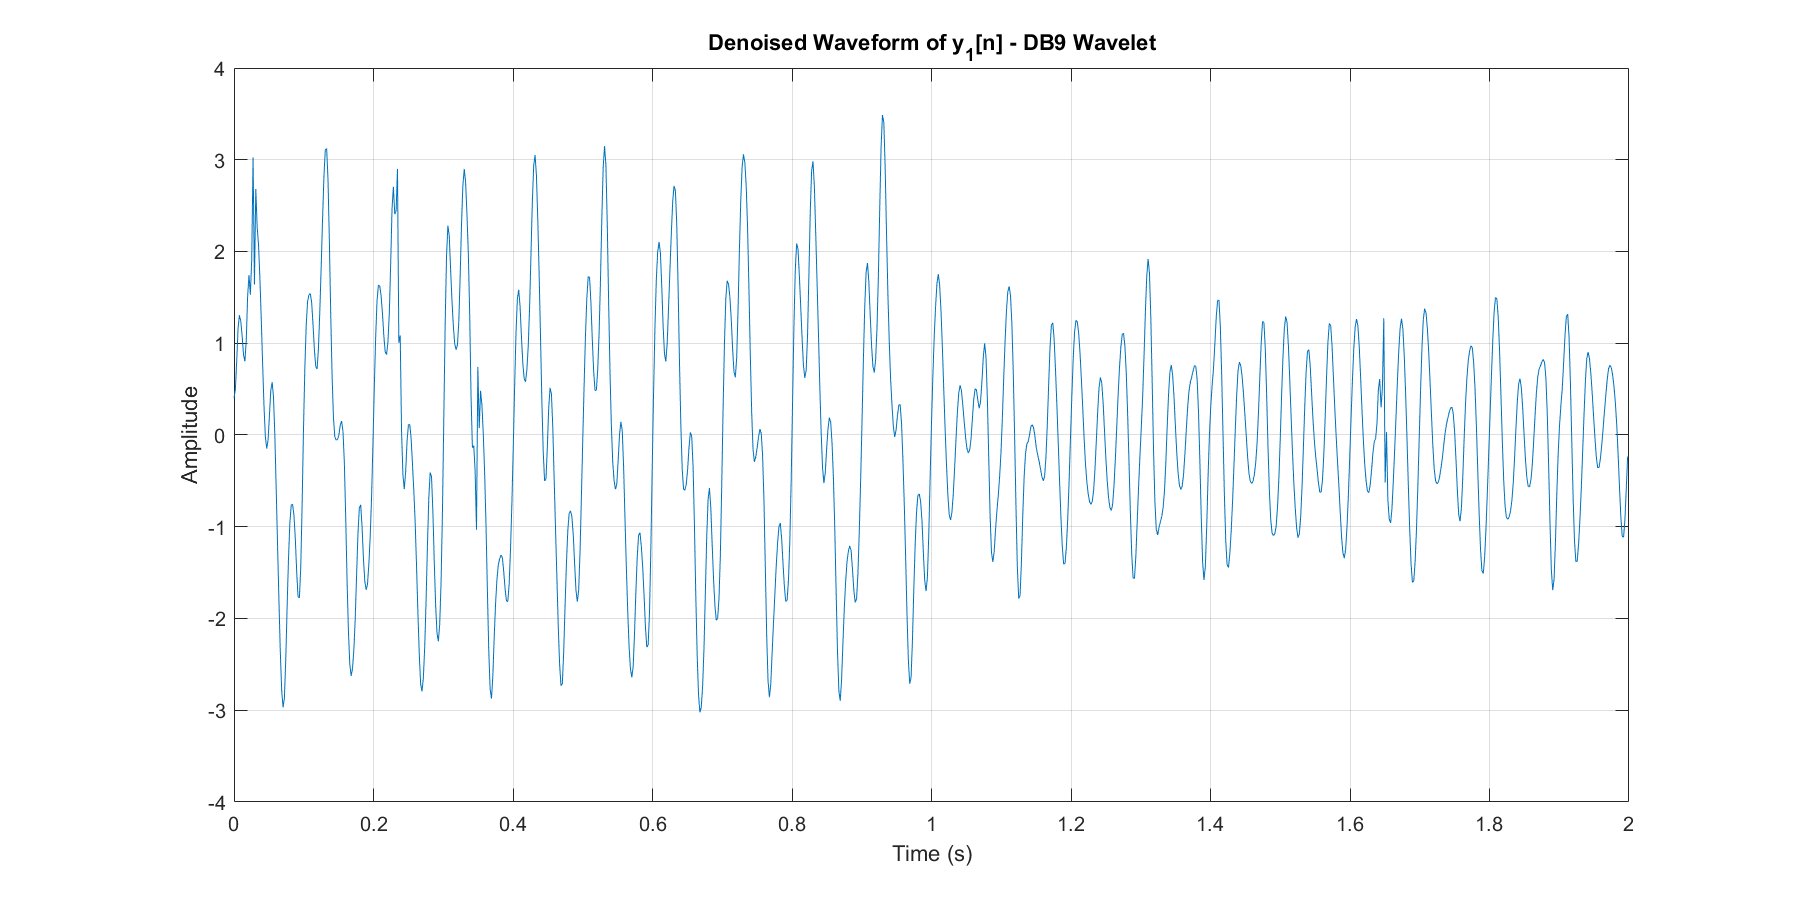


% y1[n] - DB9
figure('Name','y_1[n] - DB9 Denoised','NumberTitle','off');
set(gcf,'Position',[150 150 1200 600]);
plot(t, y1_db9_denoised);
xlabel('Time (s)');
ylabel('Amplitude');
title('Denoised Waveform of y_1[n] - DB9 Wavelet');
xlim([0 2]);
ylim([-4 4]);
grid on;

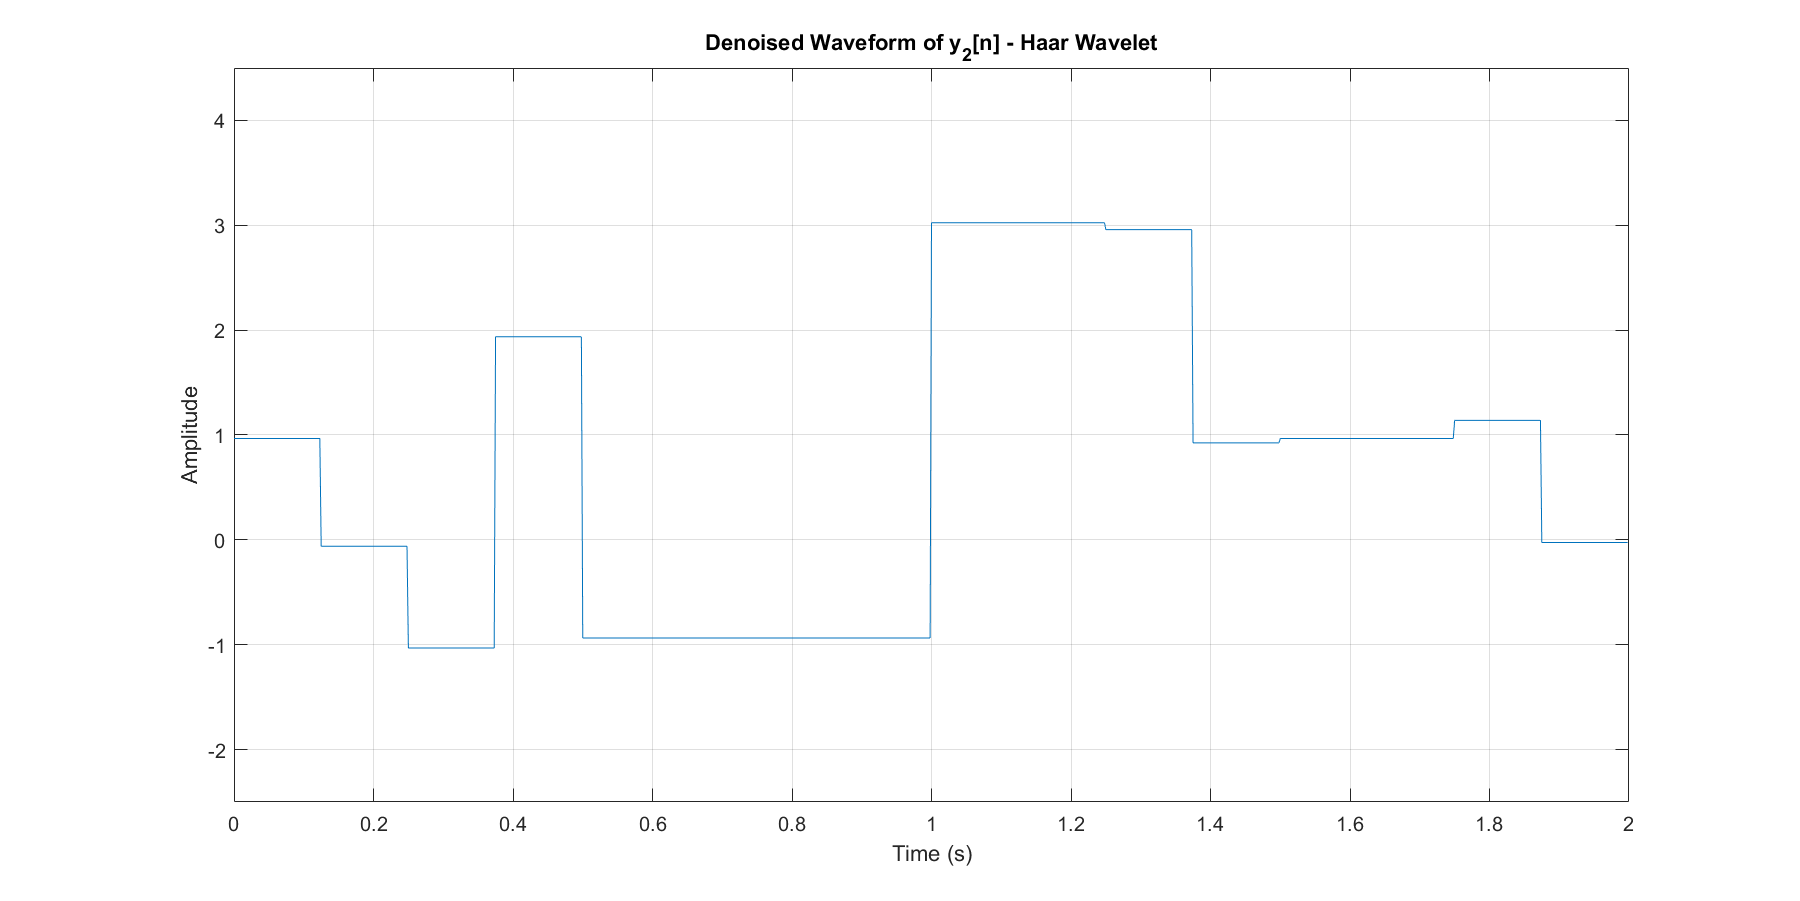


% y2[n] - Haar 
figure('Name','y_2[n] - Haar Denoised','NumberTitle','off');
set(gcf,'Position',[150 150 1200 600]);
plot(t, y2_haar_denoised);
xlabel('Time (s)');
ylabel('Amplitude');
title('Denoised Waveform of y_2[n] - Haar Wavelet');
xlim([0 2]);
ylim([-2.5 4.5]);
grid on;

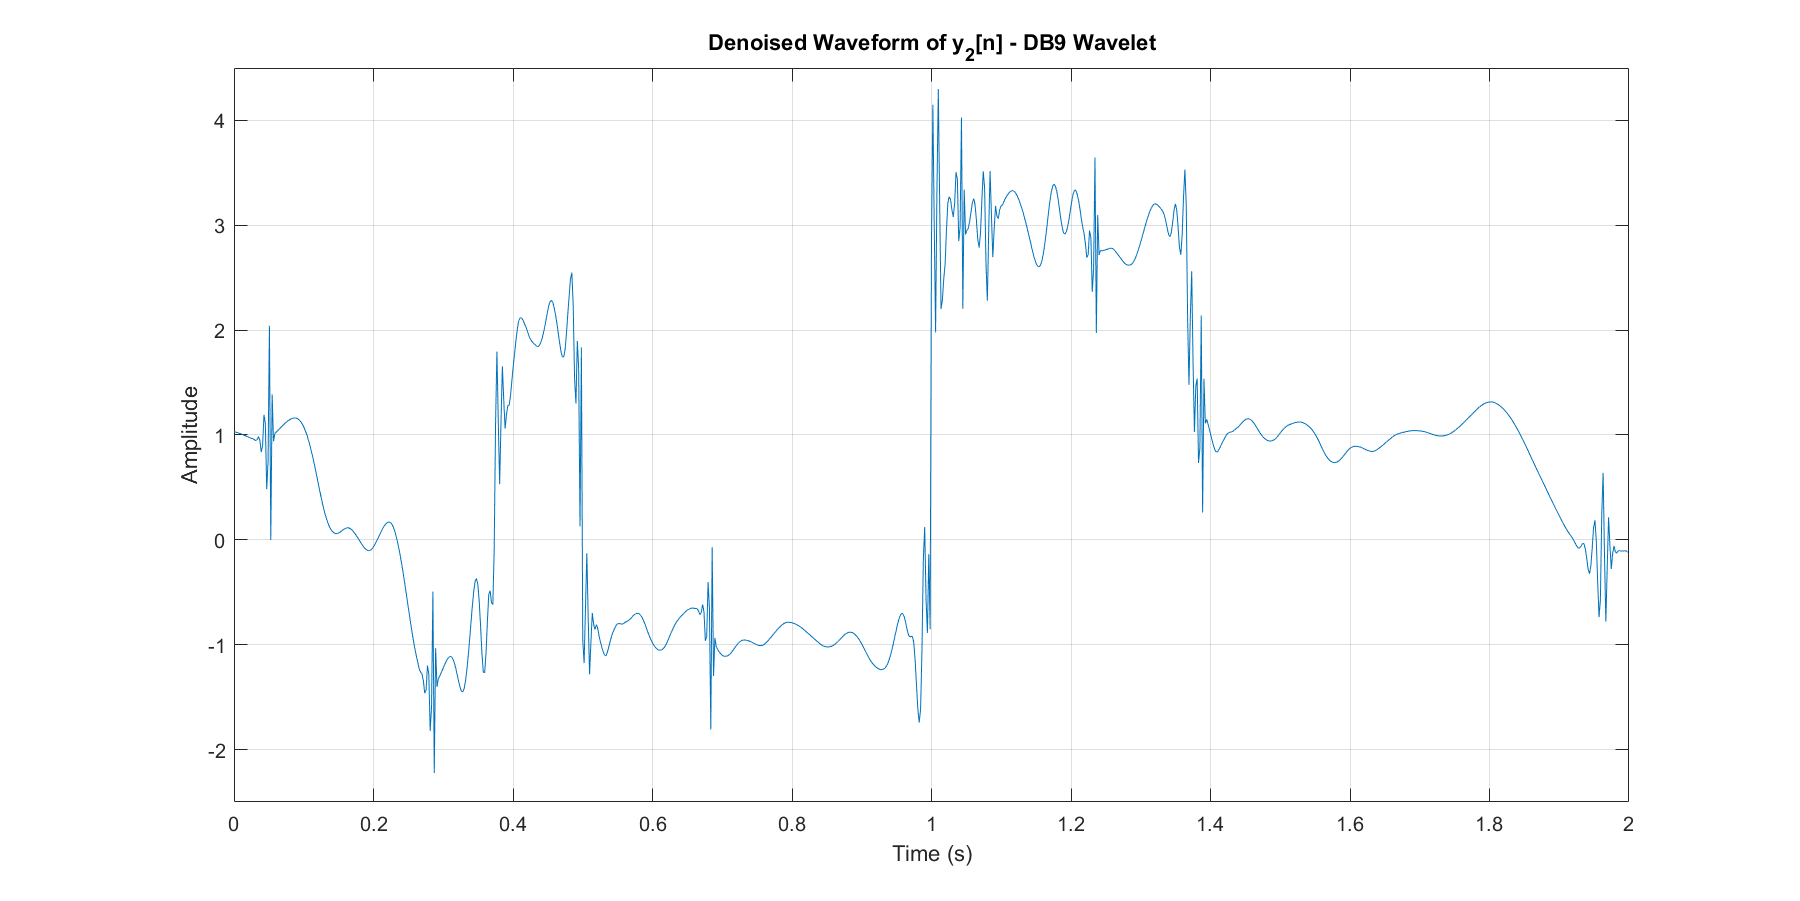


% --- y2[n] - DB9 ---
figure('Name','y_2[n] - DB9 Denoised','NumberTitle','off');
set(gcf,'Position',[150 150 1200 600]);
plot(t, y2_db9_denoised);
xlabel('Time (s)');
ylabel('Amplitude');
title('Denoised Waveform of y_2[n] - DB9 Wavelet');
xlim([0 2]);
ylim([-2.5 4.5]);
grid on;

% (iii) Calculate the RMSE between the original and denoised signal. Plot on the same plot

% Calculate the RMSE values for denoised signals

% y1[n] with Haar 
mse_y1_haar = mean((x1n - y1_haar_denoised).^2);
rmse_y1_haar = sqrt(mse_y1_haar);
fprintf('The RMSE value for y_1[n] signal when denoised using "Haar" wavelet is %.6f.\n', rmse_y1_haar);

The RMSE value for y_1[n] signal when denoised using "Haar" wavelet is 0.398471.



% y1[n] with DB9 
mse_y1_db9 = mean((x1n - y1_db9_denoised).^2);
rmse_y1_db9 = sqrt(mse_y1_db9);
fprintf('The RMSE value for y_1[n] signal when denoised using "DB9" wavelet is %.6f.\n', rmse_y1_db9);

The RMSE value for y_1[n] signal when denoised using "DB9" wavelet is 0.249889.



% y2[n] with Haar
mse_y2_haar = mean((x2n - y2_haar_denoised).^2);
rmse_y2_haar = sqrt(mse_y2_haar);
fprintf('The RMSE value for y_2[n] signal when denoised using "Haar" wavelet is %.6f.\n', rmse_y2_haar);

The RMSE value for y_2[n] signal when denoised using "Haar" wavelet is 0.059772.



% y2[n] with DB9 
mse_y2_db9 = mean((x2n - y2_db9_denoised).^2);
rmse_y2_db9 = sqrt(mse_y2_db9);
fprintf('The RMSE value for y_2[n] signal when denoised using "DB9" wavelet is %.6f.\n', rmse_y2_db9);

The RMSE value for y_2[n] signal when denoised using "DB9" wavelet is 0.280877.


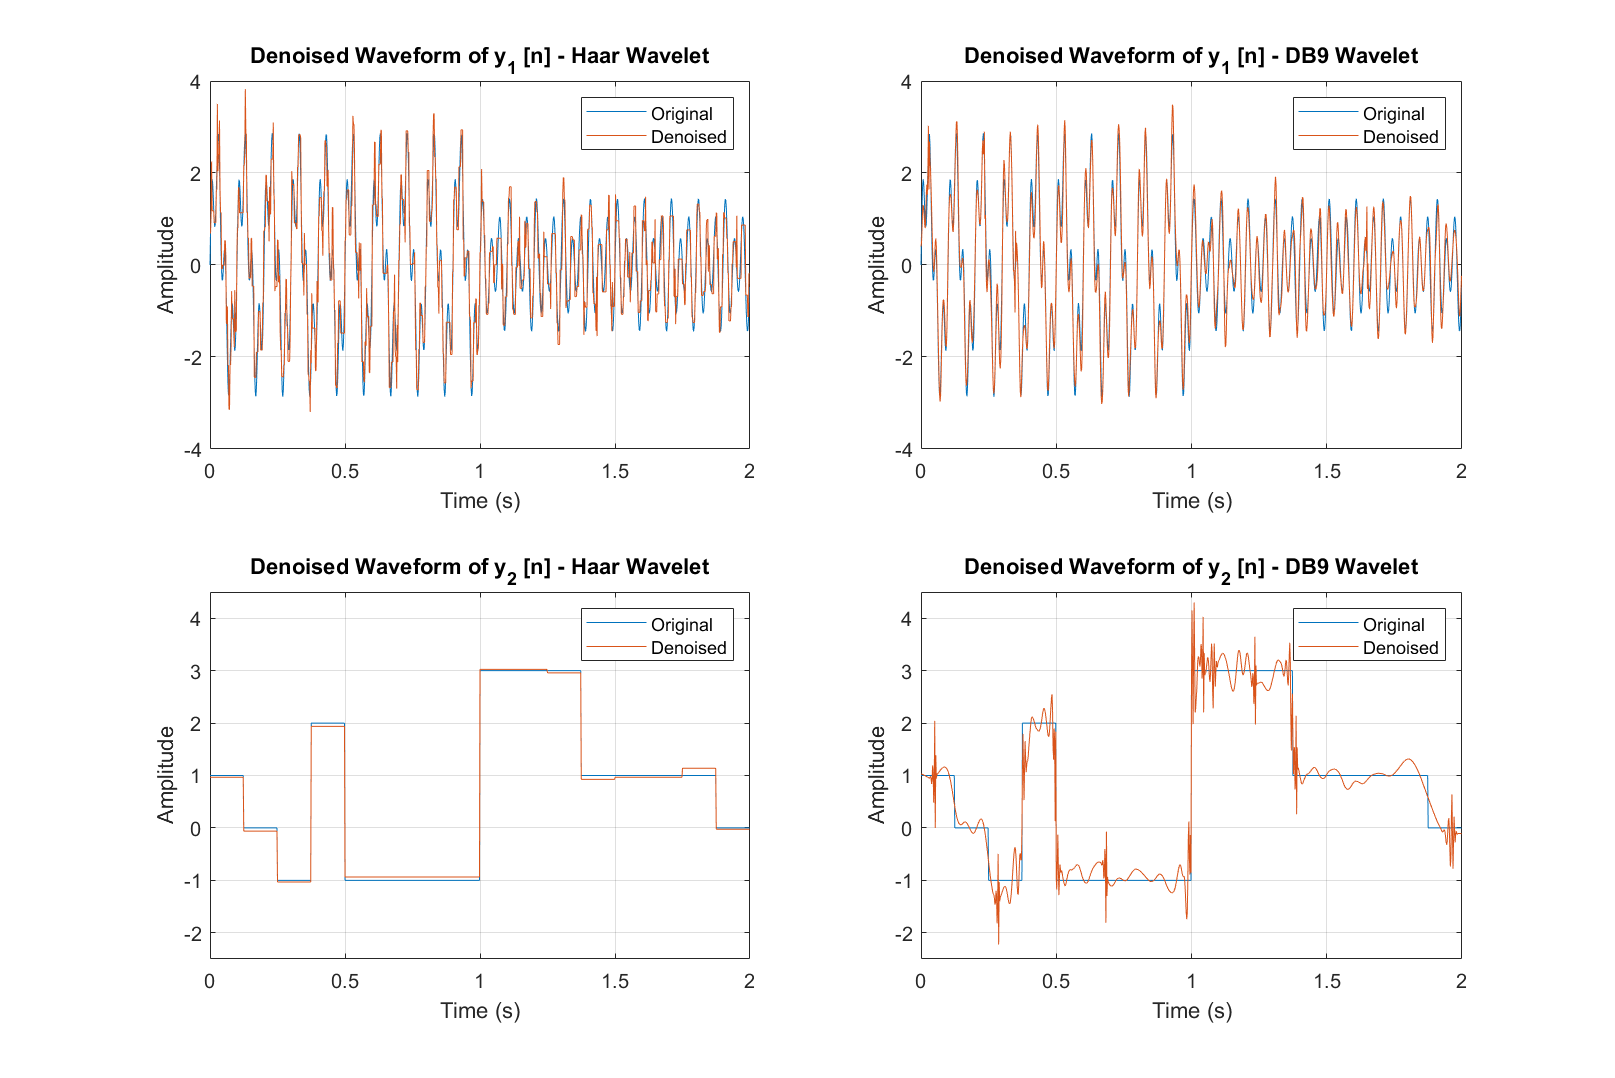

% Plot the ideal and denoised signals on the same plot
figure('Position', [100, 100, 1200, 800]);

subplot(2, 2, 1);
plot(t, x1n, t, y1_haar_denoised);
xlabel('Time (s)'); ylabel('Amplitude');
title('Denoised Waveform of y_1 [n] - Haar Wavelet');
xlim([0 2]), ylim([-4 4]);
legend('Original', 'Denoised');
grid on;

subplot(2, 2, 2);
plot(t, x1n, t, y1_db9_denoised);
xlabel('Time (s)'); ylabel('Amplitude');
title('Denoised Waveform of y_1 [n] - DB9 Wavelet');
xlim([0 2]), ylim([-4 4]);
legend('Original', 'Denoised');
grid on;

subplot(2, 2, 3);
plot(t, x2n, t, y2_haar_denoised);
xlabel('Time (s)'); ylabel('Amplitude');
title('Denoised Waveform of y_2 [n] - Haar Wavelet');
xlim([0 2]), ylim([-2.5 4.5]);
legend('Original', 'Denoised');
grid on;

subplot(2, 2, 4);
plot(t, x2n, t, y2_db9_denoised);
xlabel('Time (s)'); ylabel('Amplitude');
title('Denoised Waveform of y_2 [n] - DB9 Wavelet');
xlim([0 2]), ylim([-2.5 4.5]);
legend('Original', 'Denoised');
grid on;

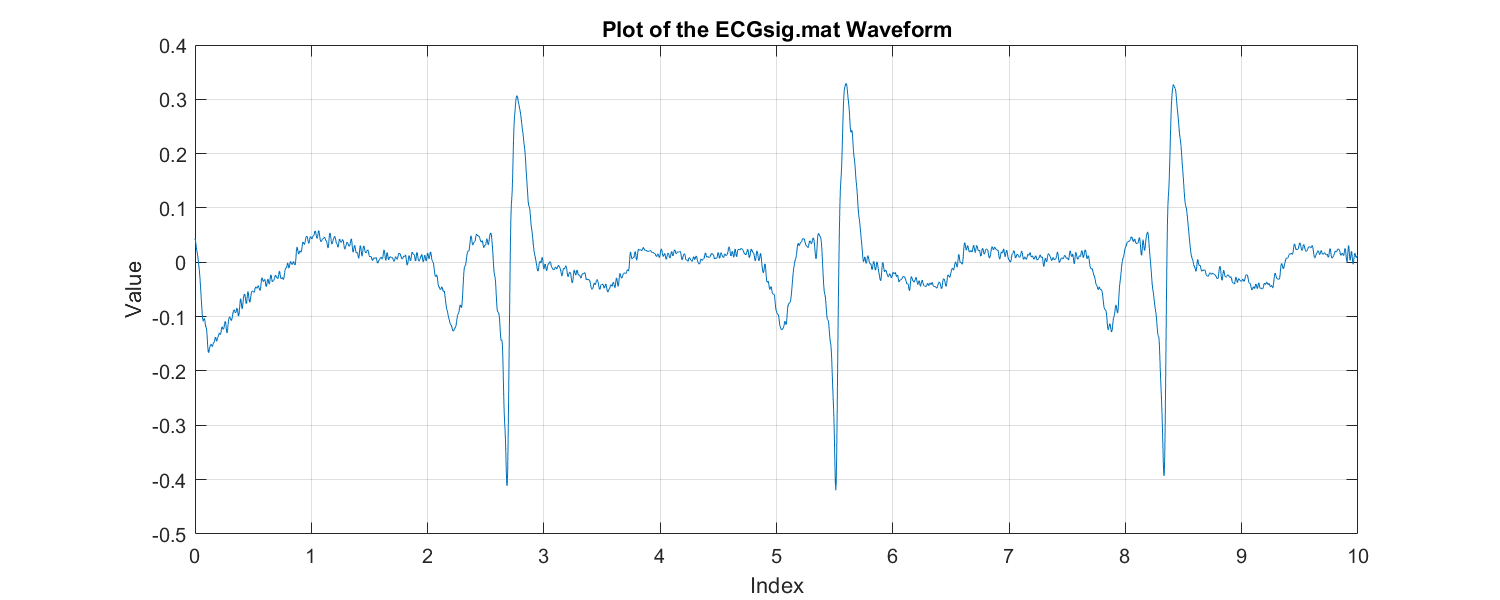

%% BM4152 Assignment 3 - Section 2.4
% Signal Compression using DWT
clear; close all; clc;
fs = 257;
% Load ECG aVR signal
load('ECGsig.mat'); 
t = (0 : length(aVR)-1) / fs; % Calculating time points

figure('Position', [100, 100, 1000, 400]);
plot(t, aVR);
title('Plot of the ECGsig.mat Waveform');
xlabel('Index'); ylabel('Value');
grid on;

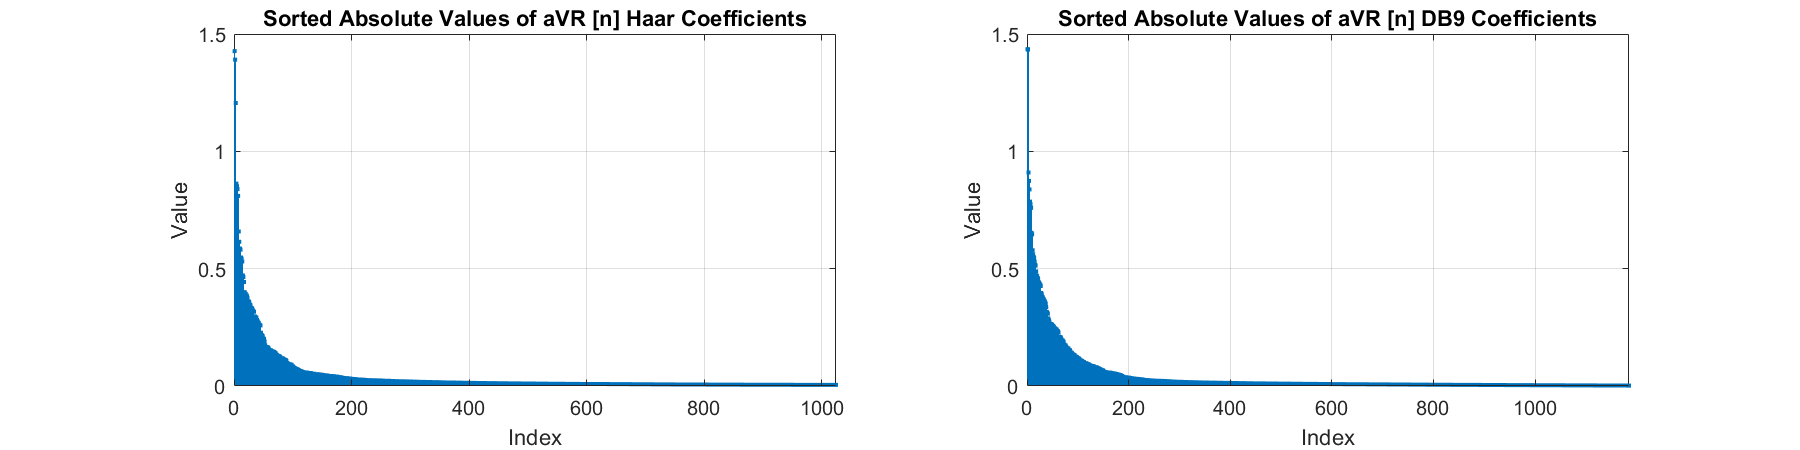


% (i) Obtain the discrete wavelet coefficients of the signal

[C_haar_aVR, L_haar_aVR] = wavedec(aVR, 10, 'haar');
[C_db9_aVR, L_db9_aVR] = wavedec(aVR, 10, 'db9');

C_haar_aVR_abs = abs(C_haar_aVR); % Calculating the absolute values
sorted_C_haar_aVR_abs = sort(C_haar_aVR_abs, 'descend');  % Sorting in descending order

C_db9_aVR_abs = abs(C_db9_aVR); % Calculating the absolute values
sorted_C_db9_aVR_abs = sort(C_db9_aVR_abs, 'descend');  % Sorting in descending order

figure('Position', [100, 100, 1200, 300]);

subplot(1, 2, 1);
stem(sorted_C_haar_aVR_abs, '.');
title('Sorted Absolute Values of aVR [n] Haar Coefficients');
xlabel('Index'); ylabel('Value');
xlim([0 1024]);
grid on;

subplot(1, 2, 2);
stem(sorted_C_db9_aVR_abs, '.');
title('Sorted Absolute Values of aVR [n] DB9 Coefficients');
xlabel('Index'); ylabel('Value');
xlim([0 1185]);
grid on;

% (ii) Find the number of coefficients which are required to represent 99% of the energy of the signal

% Calculate the total energy of the signal for both Haar and DB9 wavelets
total_energy_haar = sum(C_haar_aVR_abs.^2);  % Total energy for Haar
total_energy_db9 = sum(C_db9_aVR_abs.^2);    % Total energy for DB9

% Calculate cumulative energy to find the minimum number of coefficients for 99% energy
cumulative_energy_haar = cumsum(sorted_C_haar_aVR_abs.^2);
cumulative_energy_db9 = cumsum(sorted_C_db9_aVR_abs.^2);

% Find the threshold value and the number of coefficients that make up 99% of the energy
num_coeffs_haar_99 = find(cumulative_energy_haar >= 0.99 * total_energy_haar, 1);
num_coeffs_db9_99 = find(cumulative_energy_db9 >= 0.99 * total_energy_db9, 1);

threshold_haar = sorted_C_haar_aVR_abs(num_coeffs_haar_99);
threshold_db9 = sorted_C_db9_aVR_abs(num_coeffs_db9_99);

fprintf('Number of Haar coefficients required for 99%% energy: %d\n', num_coeffs_haar_99);

Number of Haar coefficients required for 99% energy: 177


fprintf('Number of DB9 coefficients required for 99%% energy: %d\n', num_coeffs_db9_99);

Number of DB9 coefficients required for 99% energy: 170


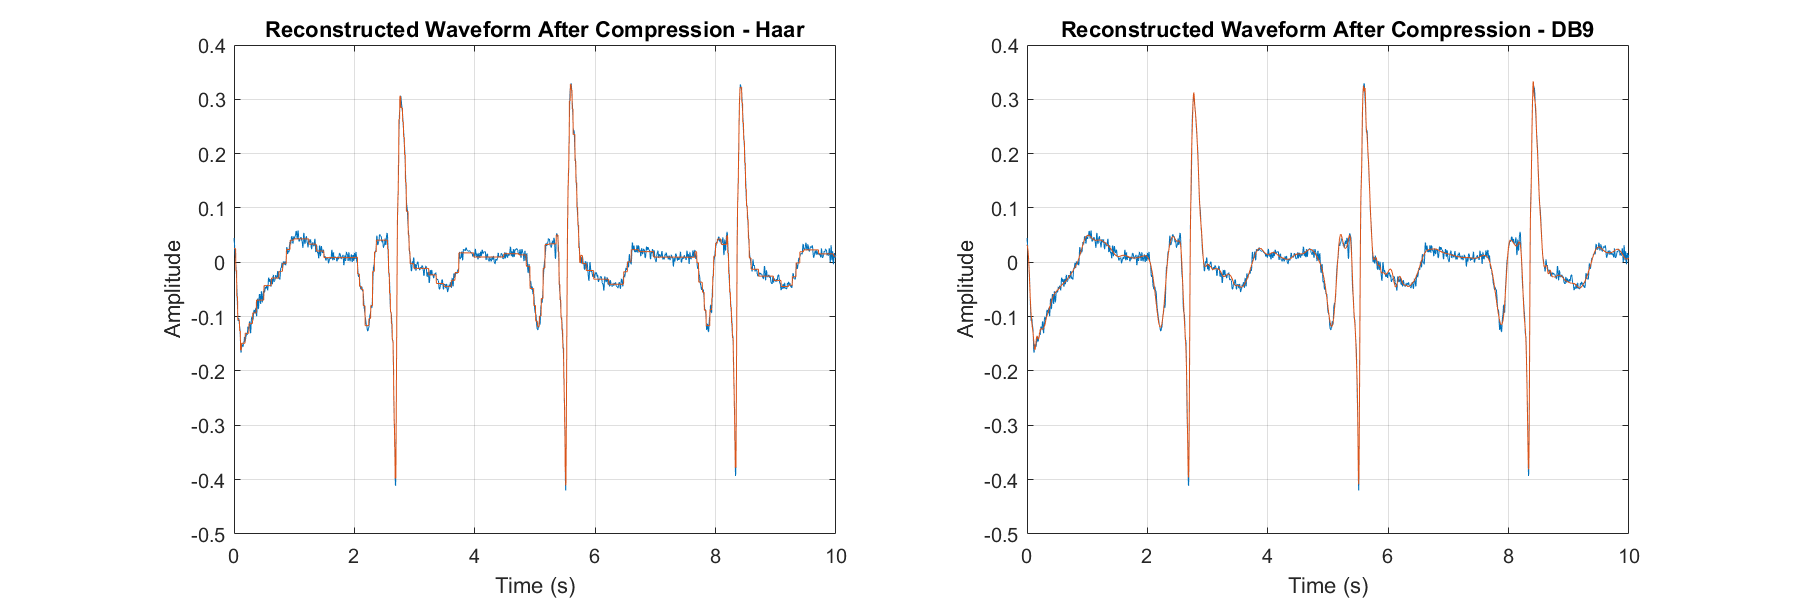

% (iii) Compress the signal and find the compression ratio. Plot the reconstructed signal

% Compress the coefficients by setting values below the threshold to zero
% For Haar wavelet
compressed_C_haar_aVR = C_haar_aVR;
compressed_C_haar_aVR(abs(compressed_C_haar_aVR) < threshold_haar) = 0;

% For DB9 wavelet
compressed_C_db9_aVR = C_db9_aVR;
compressed_C_db9_aVR(abs(compressed_C_db9_aVR) < threshold_db9) = 0;

% Reconstruct the signal using the thresholded coefficients
reconstructed_aVR_haar = waverec(compressed_C_haar_aVR, L_haar_aVR, 'haar');
reconstructed_aVR_db9 = waverec(compressed_C_db9_aVR, L_db9_aVR, 'db9');

% Plot the compressed signals after reconstruction
figure('Position', [100, 100, 1200, 400]);

subplot(1, 2, 1);
plot(t, aVR, t, reconstructed_aVR_haar);
xlabel('Time (s)'); ylabel('Amplitude');
title('Reconstructed Waveform After Compression - Haar');
grid on;

subplot(1, 2, 2);
plot(t, aVR, t, reconstructed_aVR_db9);
xlabel('Time (s)'); ylabel('Amplitude');
title('Reconstructed Waveform After Compression - DB9');
grid on;

% Calculating the compression ratio
% Count the number of non-zero coefficients after compression
non_zero_coeffs_haar = nnz(compressed_C_haar_aVR);
non_zero_coeffs_db9 = nnz(compressed_C_db9_aVR);

% Calculate the total number of original coefficients
total_coeffs_haar = length(C_haar_aVR);
total_coeffs_db9 = length(C_db9_aVR);

% Calculate compression ratios
compression_ratio_haar = total_coeffs_haar / non_zero_coeffs_haar;
compression_ratio_db9 = total_coeffs_db9 / non_zero_coeffs_db9;

fprintf('Compression ratio for Haar wavelet: %.2f\n', compression_ratio_haar);

Compression ratio for Haar wavelet: 14.56


fprintf('Compression ratio for DB9 wavelet: %.2f\n', compression_ratio_db9);

Compression ratio for DB9 wavelet: 16.08


% Calculating the RMSE values for denoised (compressed) signals

%aVR with Haar
mse_aVR_haar = mean((aVR - reconstructed_aVR_haar).^2);
rmse_aVR_haar = sqrt(mse_aVR_haar);
fprintf('The RMSE value for aVR signal when compressed using "Haar" wavelet is %.6f.\n', rmse_aVR_haar);

The RMSE value for aVR signal when compressed using "Haar" wavelet is 0.007820.



%aVR with DB9
mse_aVR_db9 = mean((aVR - reconstructed_aVR_db9).^2);
rmse_aVR_db9 = sqrt(mse_aVR_db9);
fprintf('The RMSE value for aVR signal when compressed using "DB9" wavelet is %.6f.\n', rmse_aVR_db9);

The RMSE value for aVR signal when compressed using "DB9" wavelet is 0.007129.


function plot10Dec(C, L, sig, wavlt)
    % Preparing the figure to plot all levels
    figure('Position', [100, 100, 1200, 1200]);

    
    % Plotting detail coefficients
    for k = 1:10
        subplot(6, 2, k);  % Utilizing a grid, k+1 for correct positioning
        details = detcoef(C, L, k);
        stem(details, 'filled', '.');
        title(['Detail Coefficients at Level ', num2str(k)]);
        xlim([find(details ~= 0, 1, 'first')-1 length(details)+1]);
        grid on;
    end

    % Plotting the approximation coefficients
    subplot(6, 2, 11);
    approx = appcoef(C, L, 'haar', 10);
    stem(approx, 'filled', '.');
    title(['Approximation Coefficients at Level ', num2str(10)]);
    xlim([find(approx ~= 0, 1, 'first')-1 length(approx)+1]);
    grid on;

    % Enhance plot appearance
    sgtitle(['Wavelet Decomposition of Signal ', sig, ' using ', wavlt]);
end










